# Task Data Inversion

The initial idea was to extract intrinsic connectivity from resting state data and then used these connectivity estimates when modeling task data.

So far we haven't had much success in capturing true directed connectivity parameters using sparse rDCM. 

But resting state data isn't the only place we can recover connectivity estimates from. In fact, the model with pruning is more extensively tested for task data. 

So in this notebook 

- we generate data with input (i.e. task data), 

- invert the model with pruning

- inspect connectivity and task parameter estimates

## Whole network stimulation

### Long infrequent stimulation

stim_options = get_default_stim_options("task");
on_len = 64;
off_len = 32;
num_blocks = stim_options.T/(on_len + 2*off_len);
tasktiming = repmat([zeros(1, off_len), ones(1, on_len), zeros(1, off_len)], 1, num_blocks);
stim_options.u_dt = 1/8;
tasktiming = interp1(1:stim_options.T, tasktiming, 1:stim_options.u_dt:stim_options.T, "linear");
tasktiming = double(logical(tasktiming));

stim_options.stim_node = [1,2,3];
stim_options.Tp.C = zeros(stim_options.n,length(stim_options.stim_node));
for i=1:length(stim_options.stim_node)
    stim_options.Tp.C(stim_options.stim_node(i),i) = 1;
end
stim_options.c = stim_options.Tp.C;

stim_options.u = zeros(length(tasktiming), length(stim_options.stim_node));
for i=1:length(stim_options.stim_node)
    stim_options.u(:, stim_options.stim_node(i)) = tasktiming;
end

Generate data for 20 "subjects" and invert it

num_subj = 20;
DCM_all  = cell(num_subj, 1);
options_all  = cell(num_subj, 1);
output_all  = cell(num_subj, 1);

for i=1:num_subj
    [DCM_all{i}, options_all{i}] = make_task_fmri(stim_options);
    [output_all{i}, options_all{i}] = tapas_rdcm_estimate(DCM_all{i}, 's', options_all{i}, 2);
end


Regression dynamic causal modeling (rDCM) 

Run model inversion
Processing p0: 19/19
Finalize results

Regression dynamic causal modeling (rDCM) 

Run model inversion
Processing p0: 19/19
Finalize results

Regression dynamic causal modeling (rDCM) 

Run model inversion
Processing p0: 19/19
Finalize results

Regression dynamic causal modeling (rDCM) 

Run model inversion
Processing p0: 19/19
Finalize results

Regression dynamic causal modeling (rDCM) 

Plot one example subjects network, timeseries and input

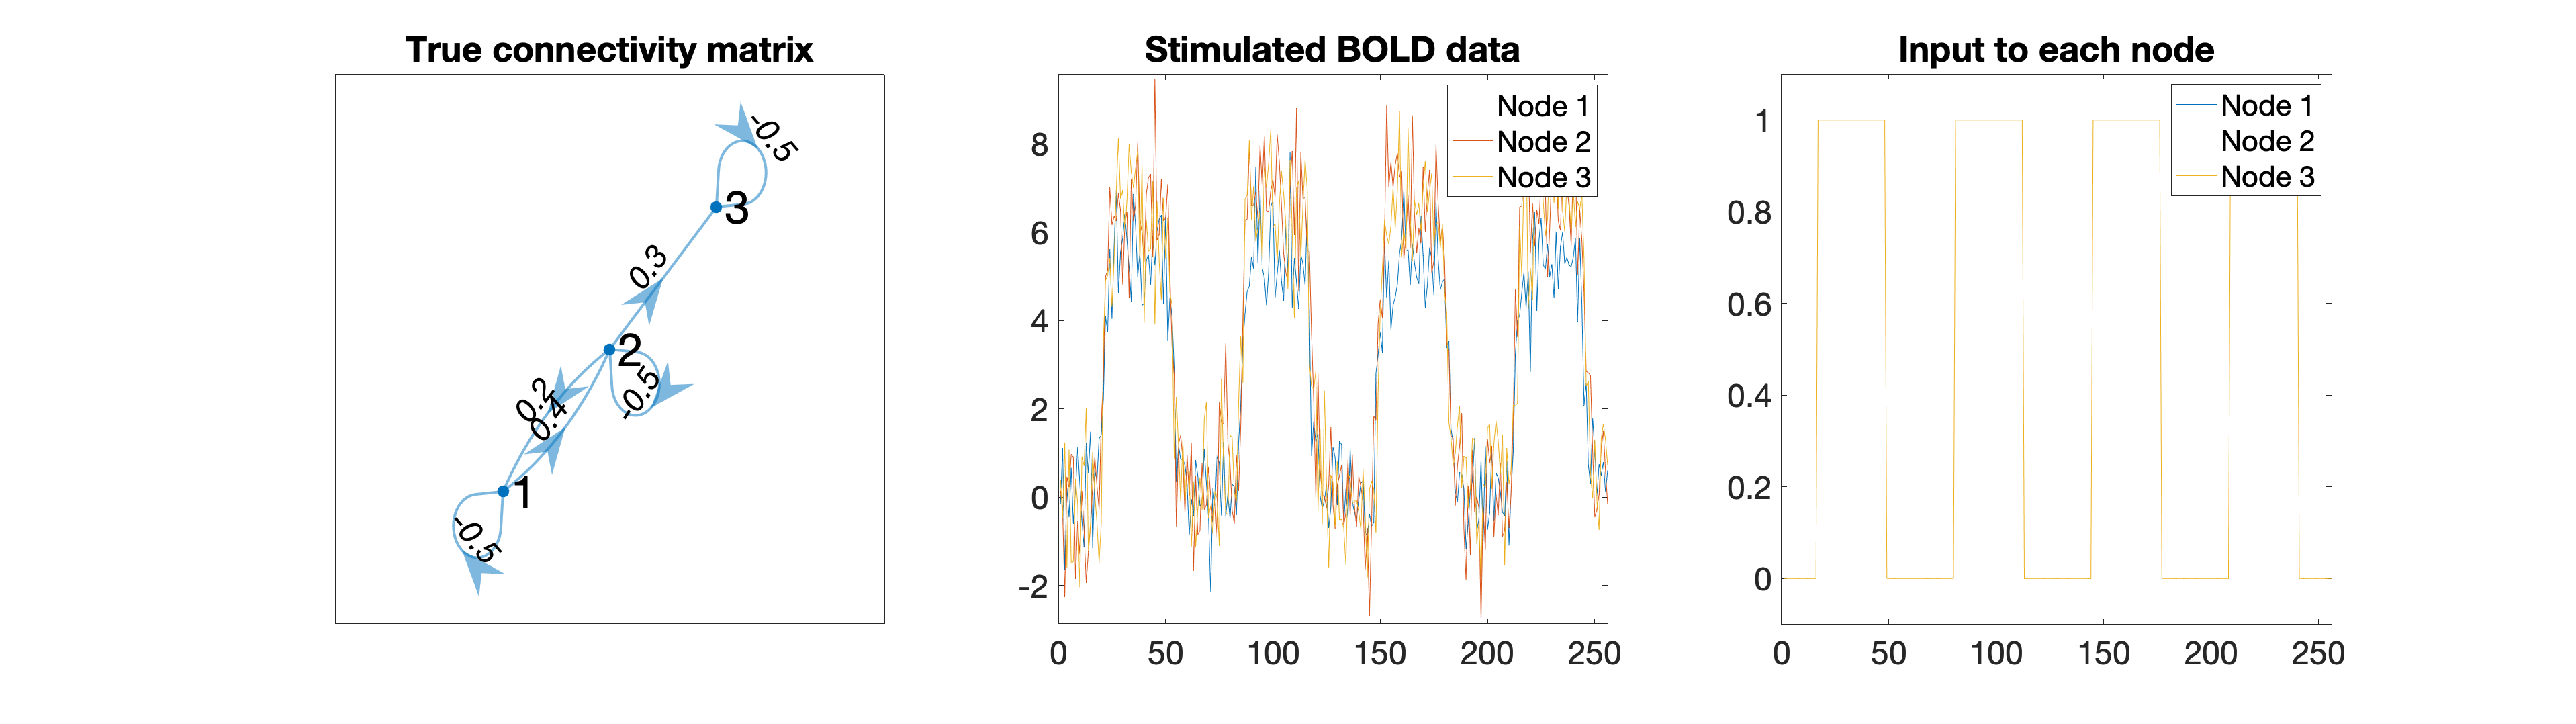

plot_sim_data(DCM_all{1})

Plot result. True vs. average of 20 estimated matrices

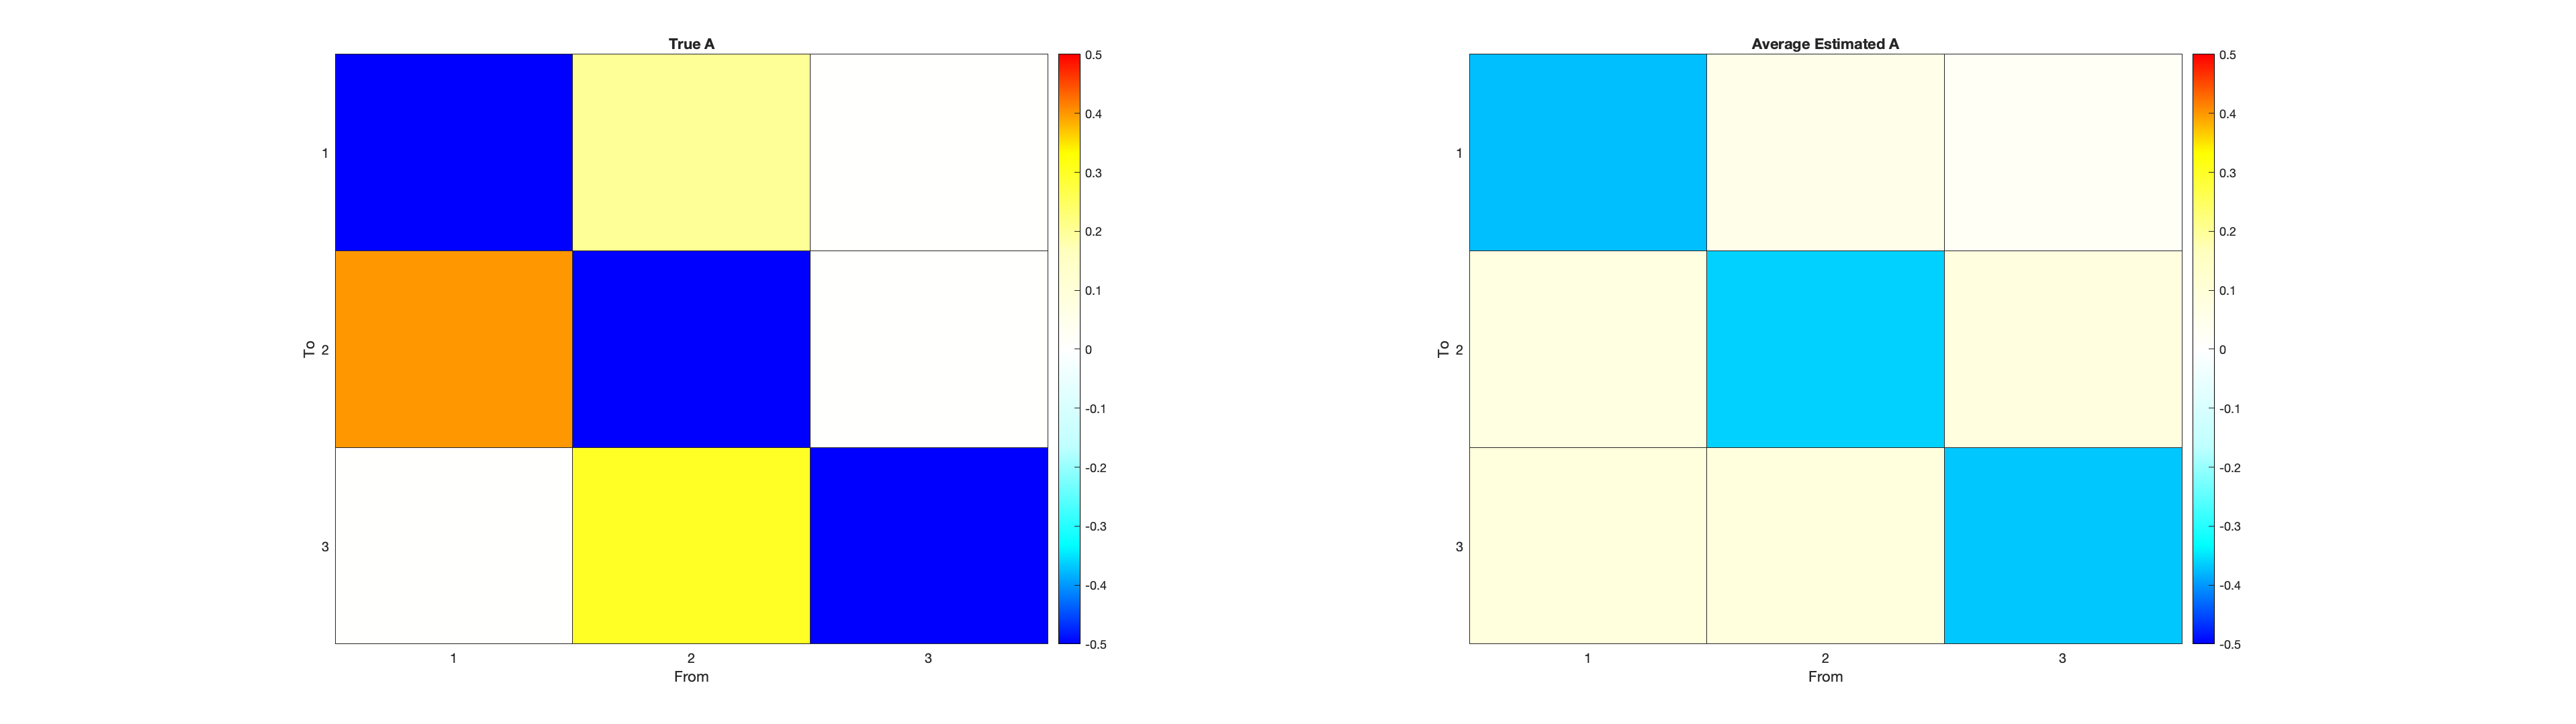

plot_true_est_connectivity(DCM_all{1}, output_all)

### Short but frequent stimulation

on_len = 16;
off_len = 8;
num_blocks = stim_options.T/(on_len + 2*off_len);
tasktiming = repmat([zeros(1, off_len), ones(1, on_len), zeros(1, off_len)], 1, num_blocks);
stim_options.u_dt = stim_options.TR/16;
tasktiming = interp1(1:stim_options.T, tasktiming, 1:stim_options.u_dt:stim_options.T, "linear");
tasktiming = double(logical(tasktiming));

stim_options.stim_node = [1,2,3];
stim_options.Tp.C = zeros(stim_options.n,length(stim_options.stim_node));
for i=1:length(stim_options.stim_node)
    stim_options.Tp.C(stim_options.stim_node(i),i) = 1;
end
stim_options.c = stim_options.Tp.C;

stim_options.u = zeros(length(tasktiming), length(stim_options.stim_node));
for i=1:length(stim_options.stim_node)
    stim_options.u(:, stim_options.stim_node(i)) = tasktiming;
end
num_subj = 20;
DCM_all  = cell(num_subj, 1);
options_all  = cell(num_subj, 1);
output_all  = cell(num_subj, 1);

for i=1:num_subj
    [DCM_all{i}, options_all{i}] = make_task_fmri(stim_options);
    [output_all{i}, options_all{i}] = tapas_rdcm_estimate(DCM_all{i}, 's', options_all{i}, 2);
end


Regression dynamic causal modeling (rDCM) 

Run model inversion
Processing p0: 19/19
Finalize results

Regression dynamic causal modeling (rDCM) 

Run model inversion
Processing p0: 19/19
Finalize results

Regression dynamic causal modeling (rDCM) 

Run model inversion
Processing p0: 19/19
Finalize results

Regression dynamic causal modeling (rDCM) 

Run model inversion
Processing p0: 19/19
Finalize results

Regression dynamic causal modeling (rDCM) 

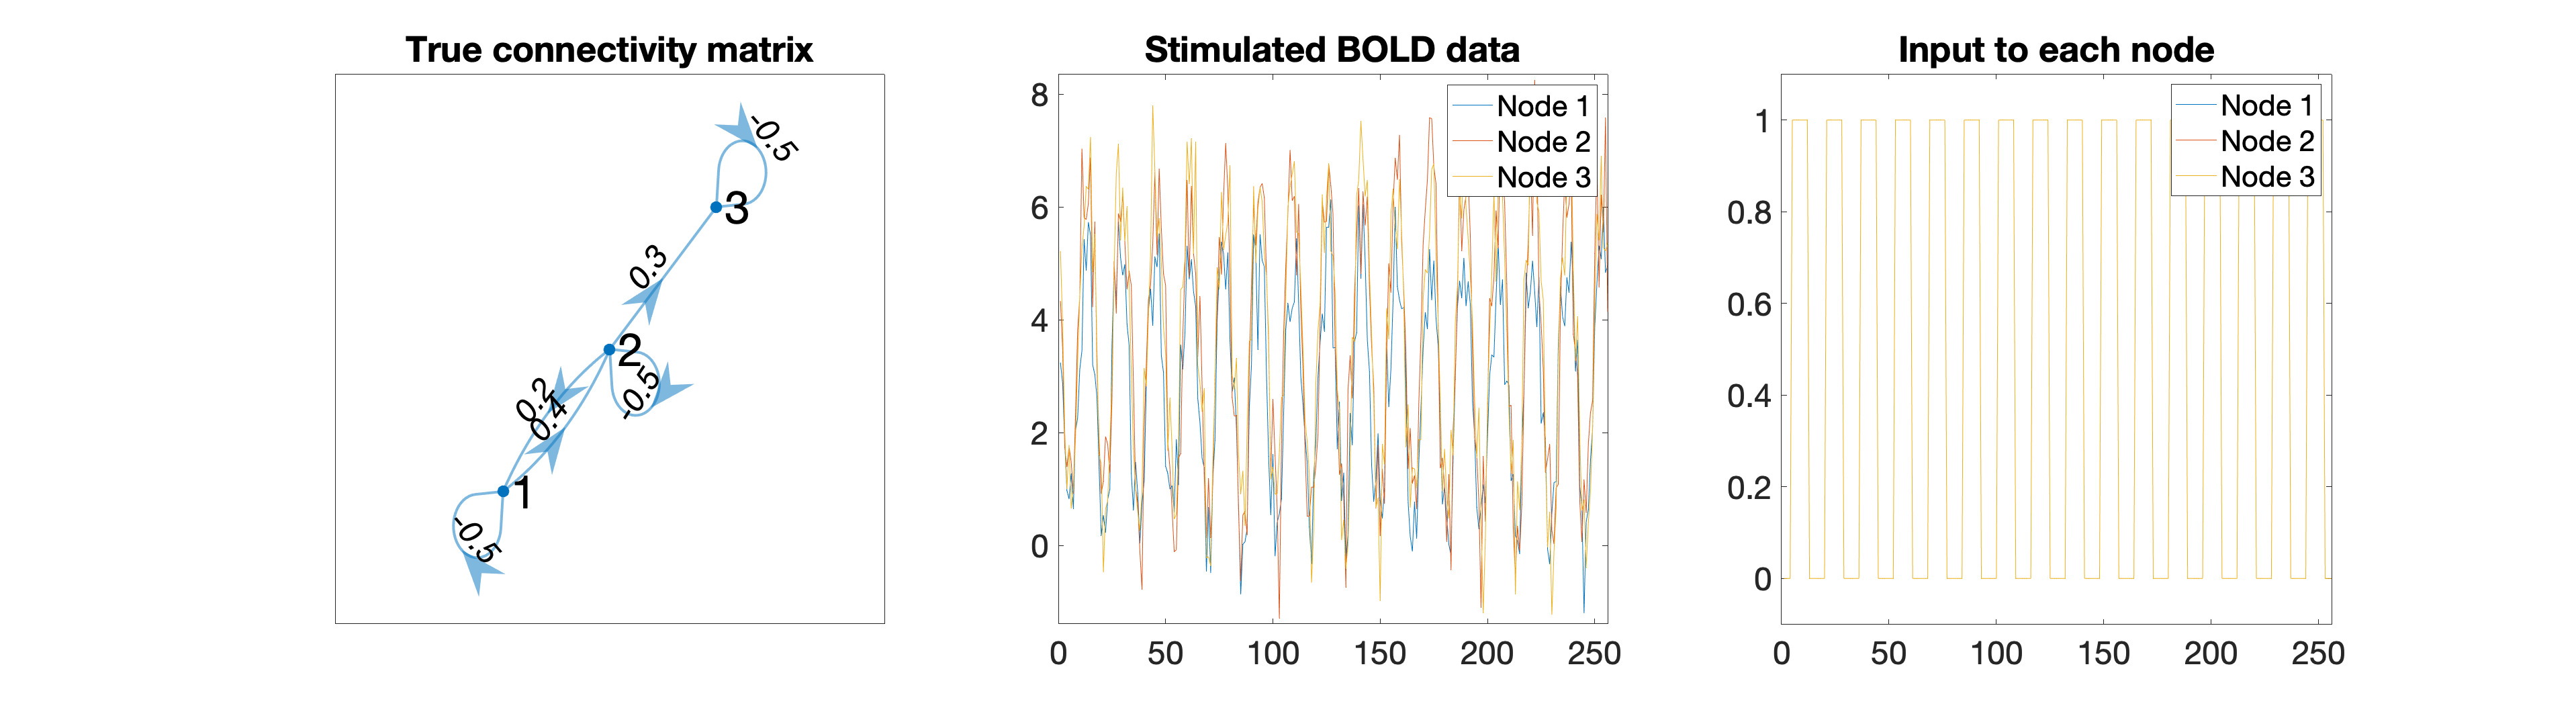

plot_sim_data(DCM_all{1})

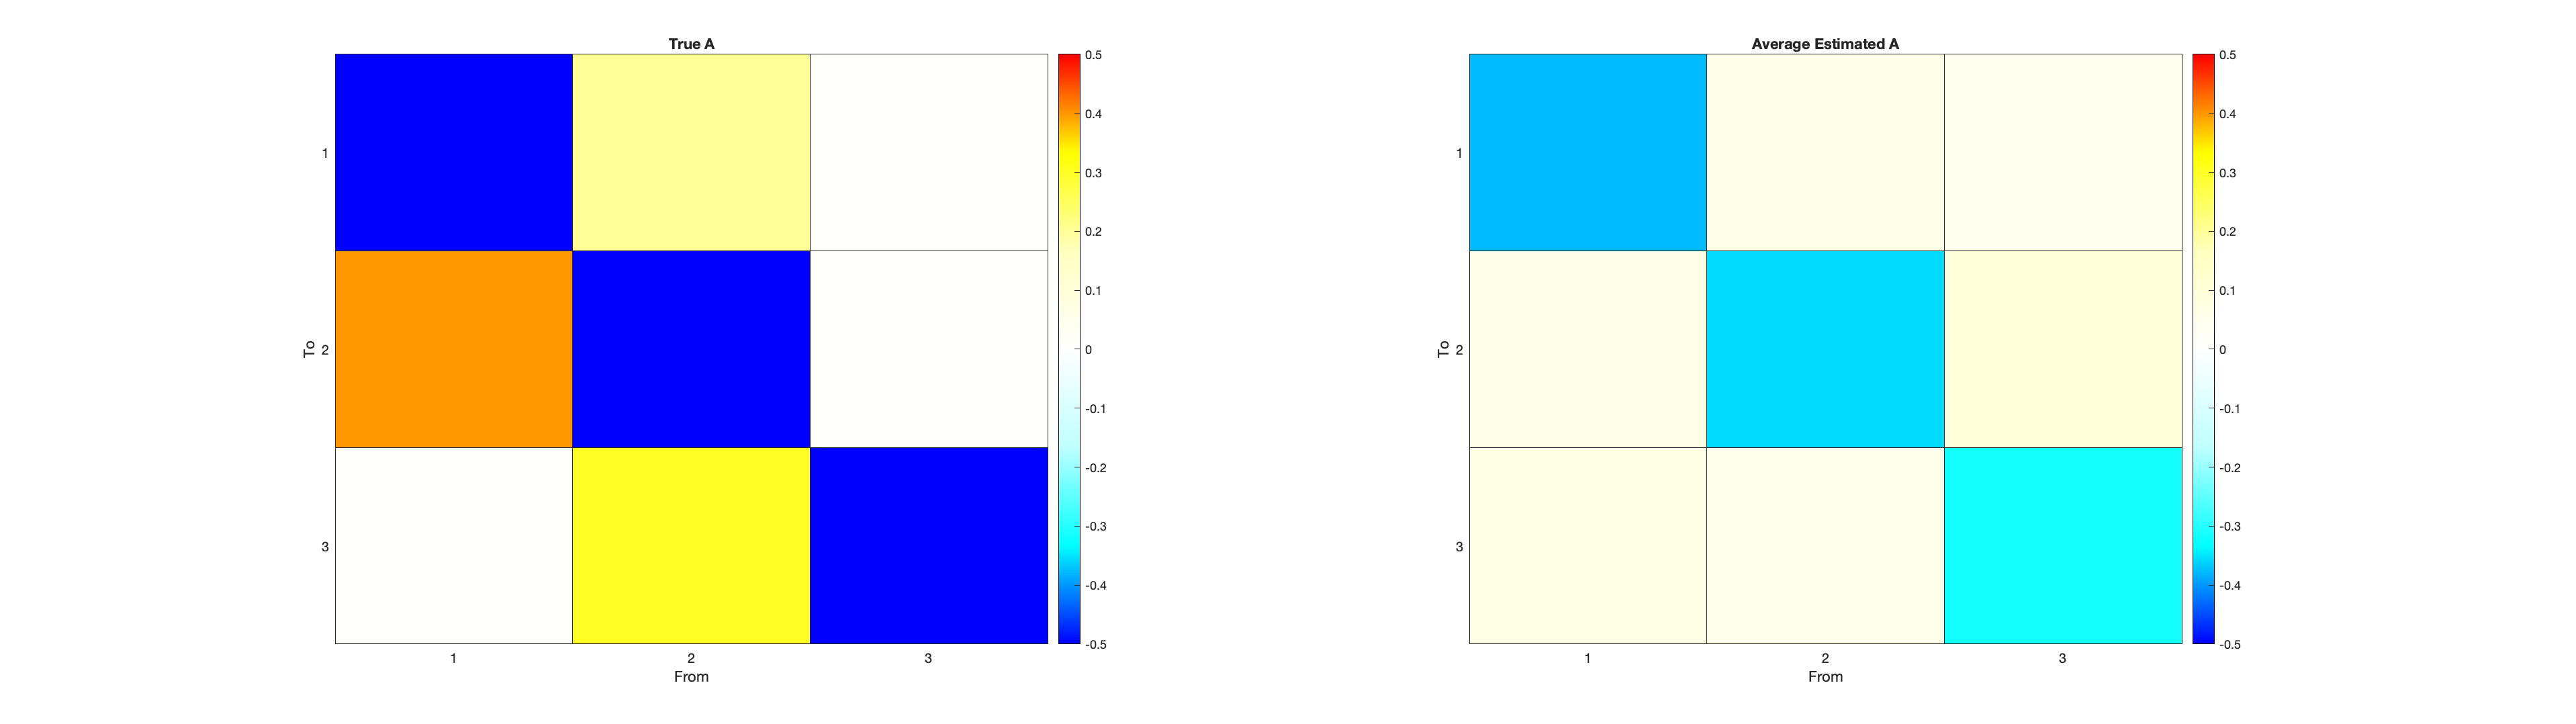

plot_true_est_connectivity(DCM_all{1}, output_all, 1)

## Single node stimulation

### Long infrequent stimulation

on_len = 64;
off_len = 32;
num_blocks = stim_options.T/(on_len + 2*off_len);
tasktiming = repmat([zeros(1, off_len), ones(1, on_len), zeros(1, off_len)], 1, num_blocks);
stim_options.u_dt = 1/8;
tasktiming = interp1(1:stim_options.T, tasktiming, 1:stim_options.u_dt:stim_options.T, "linear");
tasktiming = double(logical(tasktiming));

stim_options.stim_node = 2;
stim_options.Tp.C = zeros(stim_options.n,length(stim_options.stim_node));
for i=1:length(stim_options.stim_node)
    stim_options.Tp.C(stim_options.stim_node(i),i) = 1;
end
stim_options.c = stim_options.Tp.C;

stim_options.u = zeros(length(tasktiming), length(stim_options.stim_node));
for i=1:length(stim_options.stim_node)
    stim_options.u(:, stim_options.stim_node(i)) = tasktiming;
end

num_subj = 20;
DCM_all  = cell(num_subj, 1);
options_all  = cell(num_subj, 1);
output_all  = cell(num_subj, 1);

for i=1:num_subj
    [DCM_all{i}, options_all{i}] = make_task_fmri(stim_options);
    [output_all{i}, options_all{i}] = tapas_rdcm_estimate(DCM_all{i}, 's', options_all{i}, 2);
end


Regression dynamic causal modeling (rDCM) 

Run model inversion
Processing p0: 19/19
Finalize results

Regression dynamic causal modeling (rDCM) 

Run model inversion
Processing p0: 19/19
Finalize results

Regression dynamic causal modeling (rDCM) 

Run model inversion
Processing p0: 19/19
Finalize results

Regression dynamic causal modeling (rDCM) 

Run model inversion
Processing p0: 19/19
Finalize results

Regression dynamic causal modeling (rDCM) 

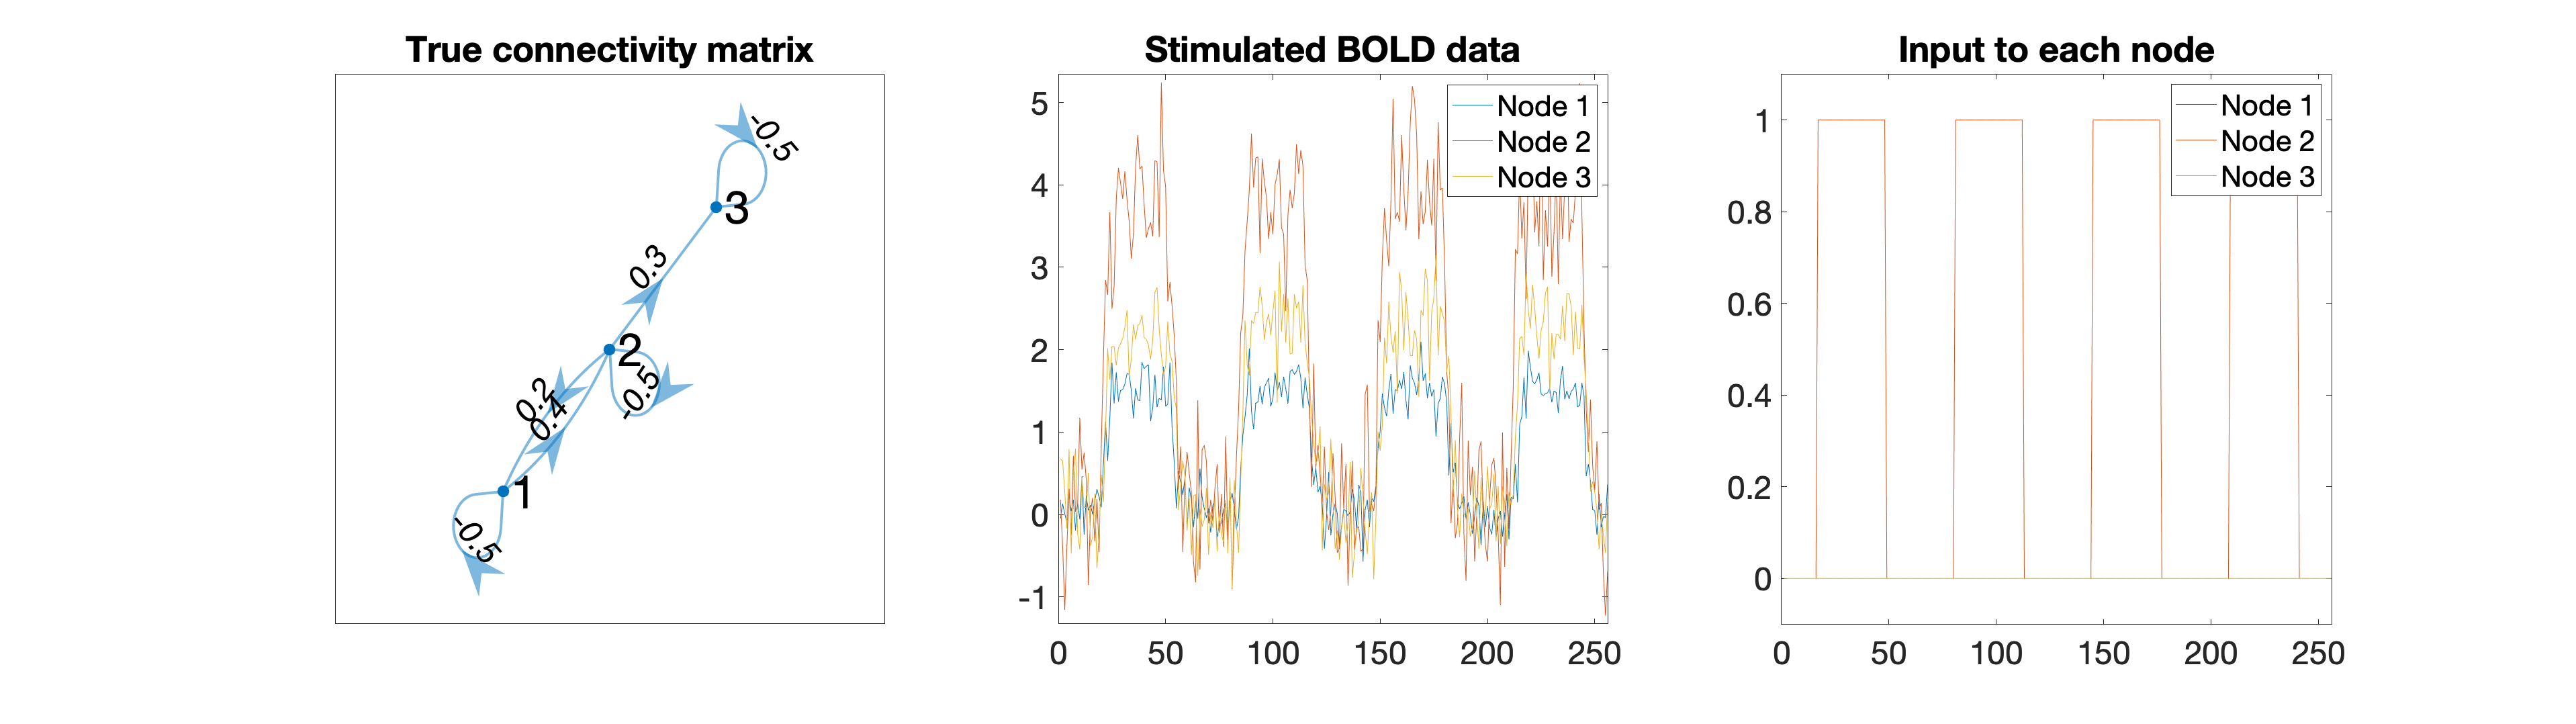

plot_sim_data(DCM_all{1})

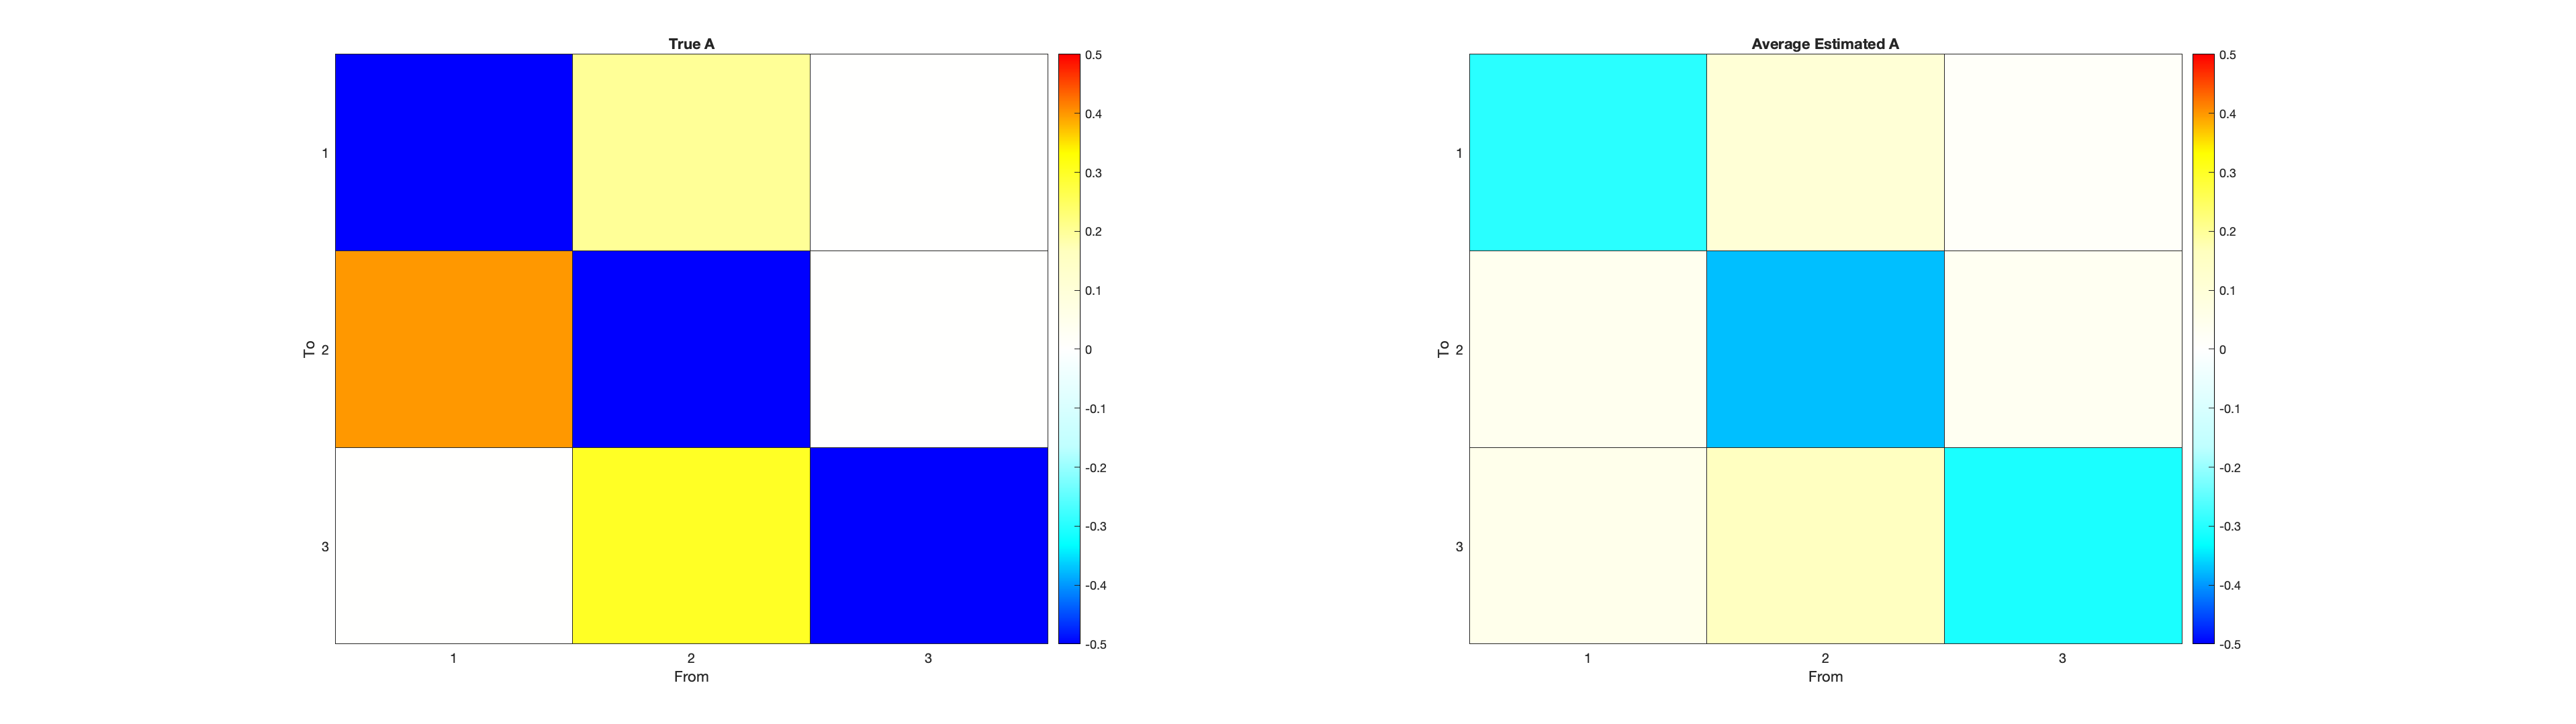

plot_true_est_connectivity(DCM_all{1}, output_all, 1)

### Short but frequent stimulation

on_len = 16;
off_len = 8;
num_blocks = stim_options.T/(on_len + 2*off_len);
tasktiming = repmat([zeros(1, off_len), ones(1, on_len), zeros(1, off_len)], 1, num_blocks);
stim_options.u_dt = stim_options.TR/16;
tasktiming = interp1(1:stim_options.T, tasktiming, 1:stim_options.u_dt:stim_options.T, "linear");
tasktiming = double(logical(tasktiming));

stim_options.stim_node = 2;
stim_options.Tp.C = zeros(stim_options.n,length(stim_options.stim_node));
for i=1:length(stim_options.stim_node)
    stim_options.Tp.C(stim_options.stim_node(i),i) = 1;
end
stim_options.c = stim_options.Tp.C;

stim_options.u = zeros(length(tasktiming), length(stim_options.stim_node));
for i=1:length(stim_options.stim_node)
    stim_options.u(:, stim_options.stim_node(i)) = tasktiming;
end

num_subj = 20;
DCM_all  = cell(num_subj, 1);
options_all  = cell(num_subj, 1);
output_all  = cell(num_subj, 1);

for i=1:num_subj
    [DCM_all{i}, options_all{i}] = make_task_fmri(stim_options);
    [output_all{i}, options_all{i}] = tapas_rdcm_estimate(DCM_all{i}, 's', options_all{i}, 2);
end


Regression dynamic causal modeling (rDCM) 

Run model inversion
Processing p0: 19/19
Finalize results

Regression dynamic causal modeling (rDCM) 

Run model inversion
Processing p0: 19/19
Finalize results

Regression dynamic causal modeling (rDCM) 

Run model inversion
Processing p0: 19/19
Finalize results

Regression dynamic causal modeling (rDCM) 

Run model inversion
Processing p0: 19/19
Finalize results

Regression dynamic causal modeling (rDCM) 

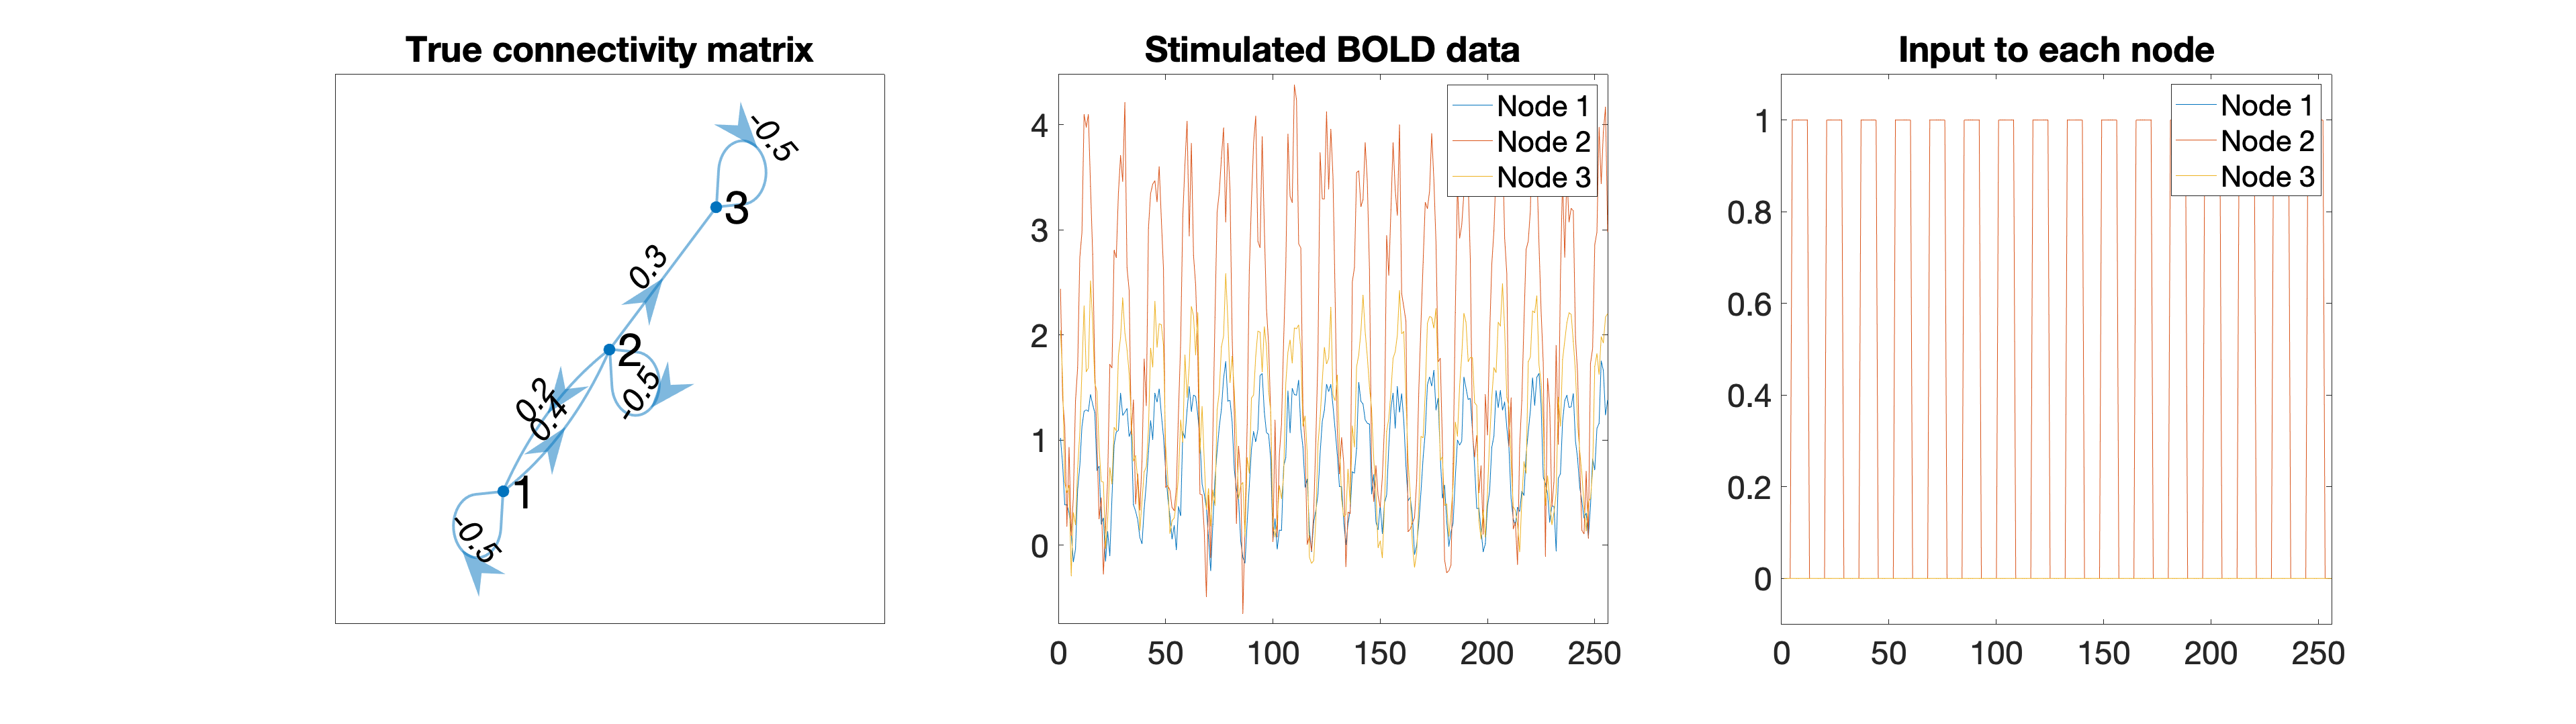

plot_sim_data(DCM_all{1})

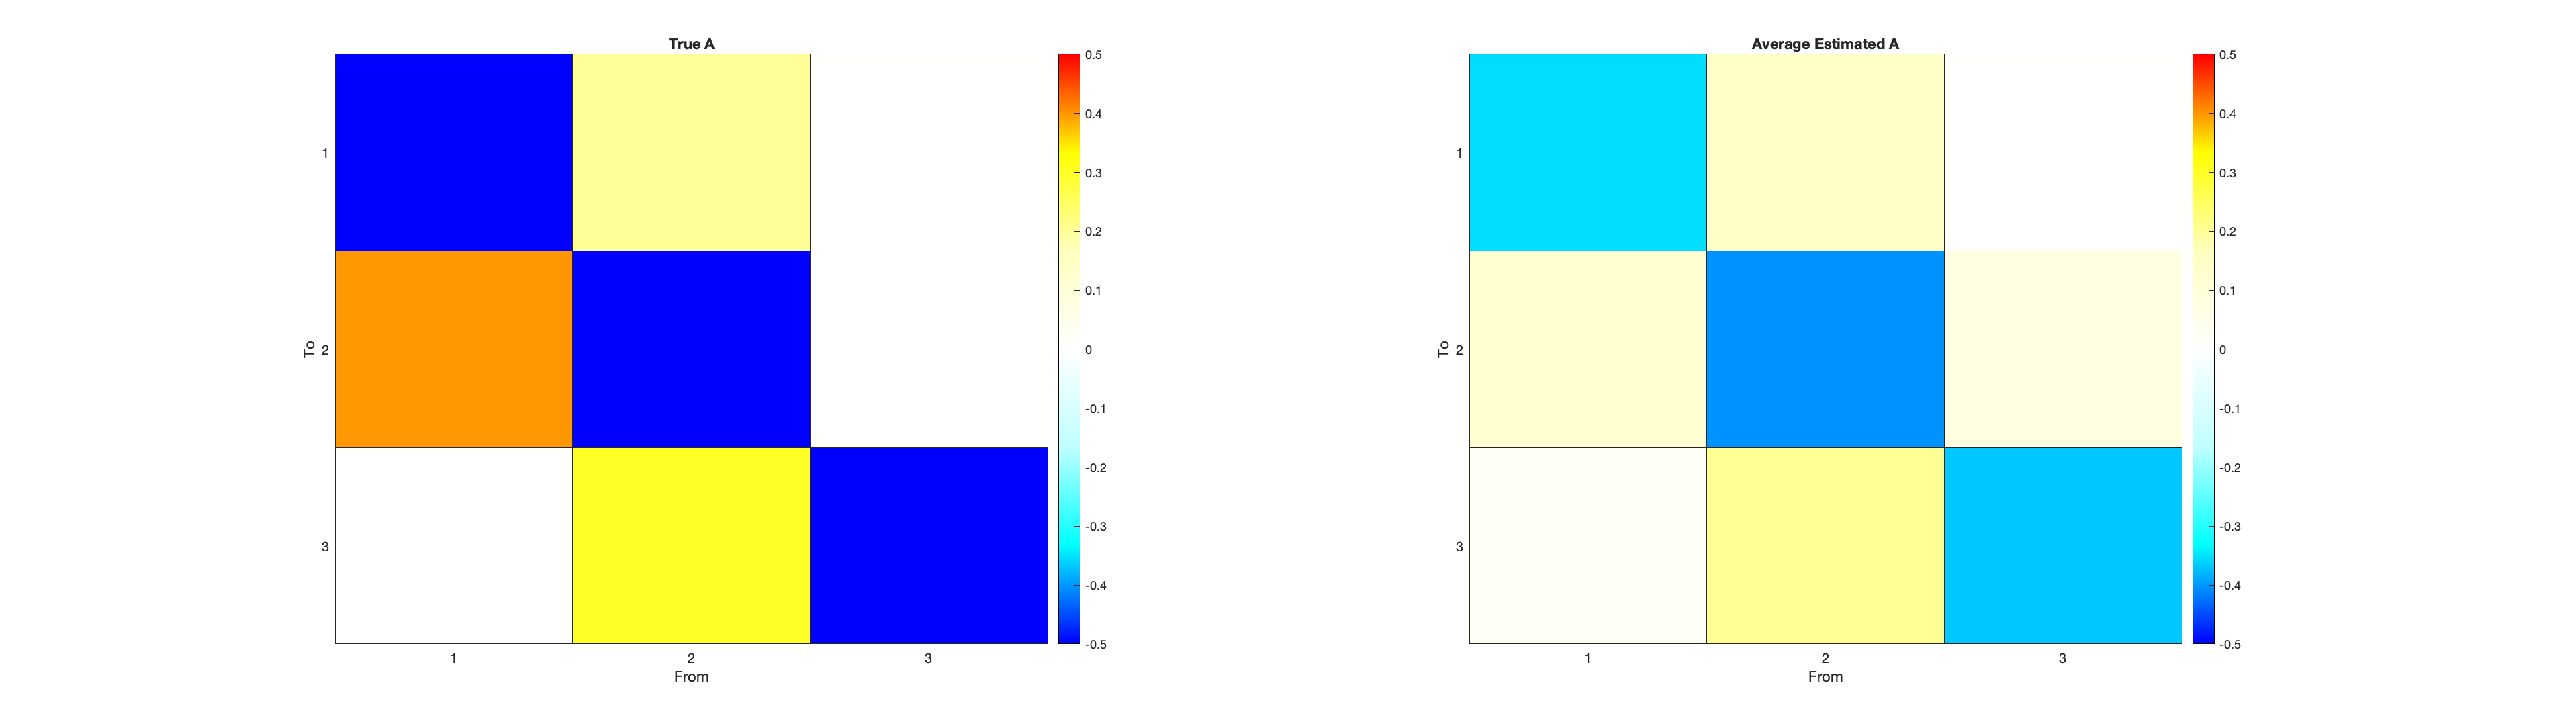

plot_true_est_connectivity(DCM_all{1}, output_all, 1)

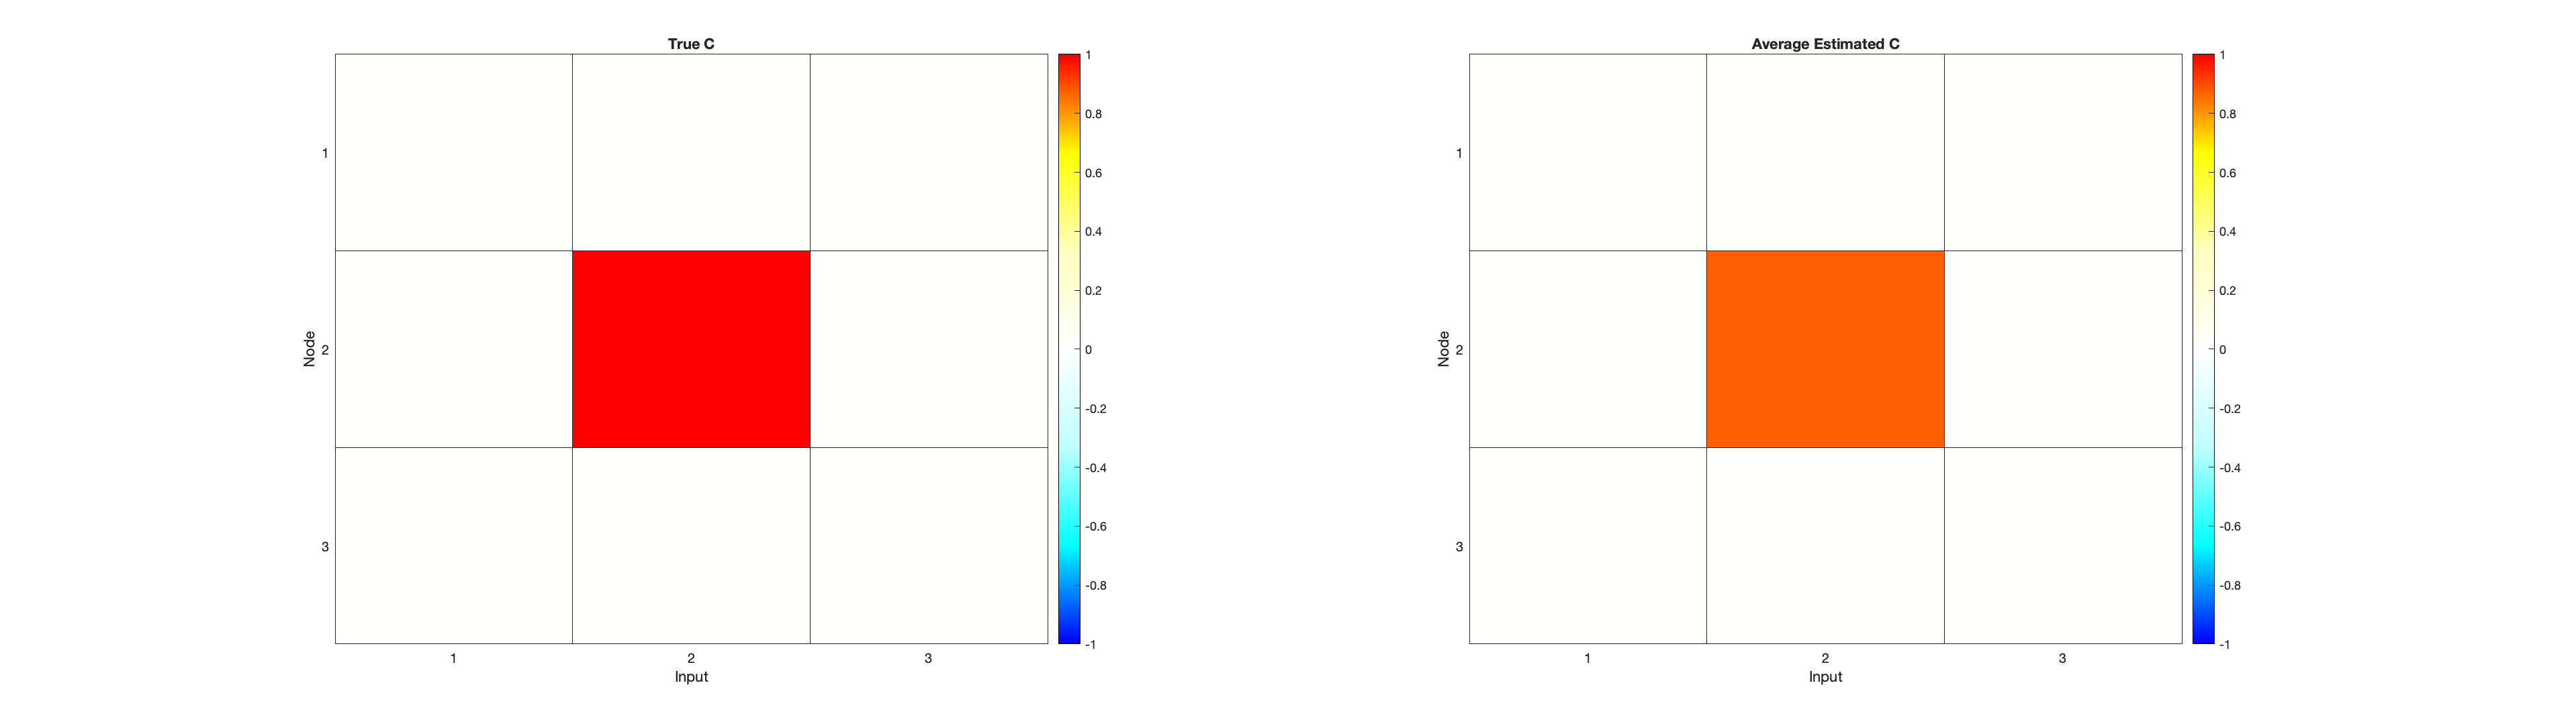

plot_true_est_taskstim(DCM_all{1}, output_all)

### Short frequent task stimulating different nodes in different blocks

on_len = 16;
off_len = 8;
num_blocks = 15;
stim_options.T = num_blocks * (on_len + 2*off_len);
tasktiming = repmat([zeros(1, off_len), ones(1, on_len), zeros(1, off_len)], 1, num_blocks);
stim_options.u_dt = stim_options.TR/16;
tasktiming = interp1(1:stim_options.T, tasktiming, 1:stim_options.u_dt:stim_options.T, "linear");
tasktiming = double(logical(tasktiming));

stim_options.stim_node = [1, 2, 3];
stim_options.Tp.C = zeros(stim_options.n,length(stim_options.stim_node));
for i=1:length(stim_options.stim_node)
    stim_options.Tp.C(stim_options.stim_node(i),i) = 1;
end
stim_options.c = stim_options.Tp.C;

stim_options.u = zeros(length(tasktiming), length(stim_options.stim_node));
for i=1:length(stim_options.stim_node)
    stim_options.u(:, stim_options.stim_node(i)) = tasktiming;
end

%Stimulate each node at different blocks (5 blocks at a time)
node_stim_dur = 5*(on_len + 2*off_len)/stim_options.u_dt;

for i=1:stim_options.n
    cur_nodes = stim_options.stim_node(stim_options.stim_node~=i);
    stim_options.u((i-1)*node_stim_dur+1:node_stim_dur*i, cur_nodes) = 0; 
end

num_subj = 20;
DCM_all  = cell(num_subj, 1);
options_all  = cell(num_subj, 1);
output_all  = cell(num_subj, 1);

for i=1:num_subj
    [DCM_all{i}, options_all{i}] = make_task_fmri(stim_options);
    [output_all{i}, options_all{i}] = tapas_rdcm_estimate(DCM_all{i}, 's', options_all{i}, 2);
end


Regression dynamic causal modeling (rDCM) 

Run model inversion
Processing p0: 19/19
Finalize results

Regression dynamic causal modeling (rDCM) 

Run model inversion
Processing p0: 19/19
Finalize results

Regression dynamic causal modeling (rDCM) 

Run model inversion
Processing p0: 19/19
Finalize results

Regression dynamic causal modeling (rDCM) 

Run model inversion
Processing p0: 19/19
Finalize results

Regression dynamic causal modeling (rDCM) 

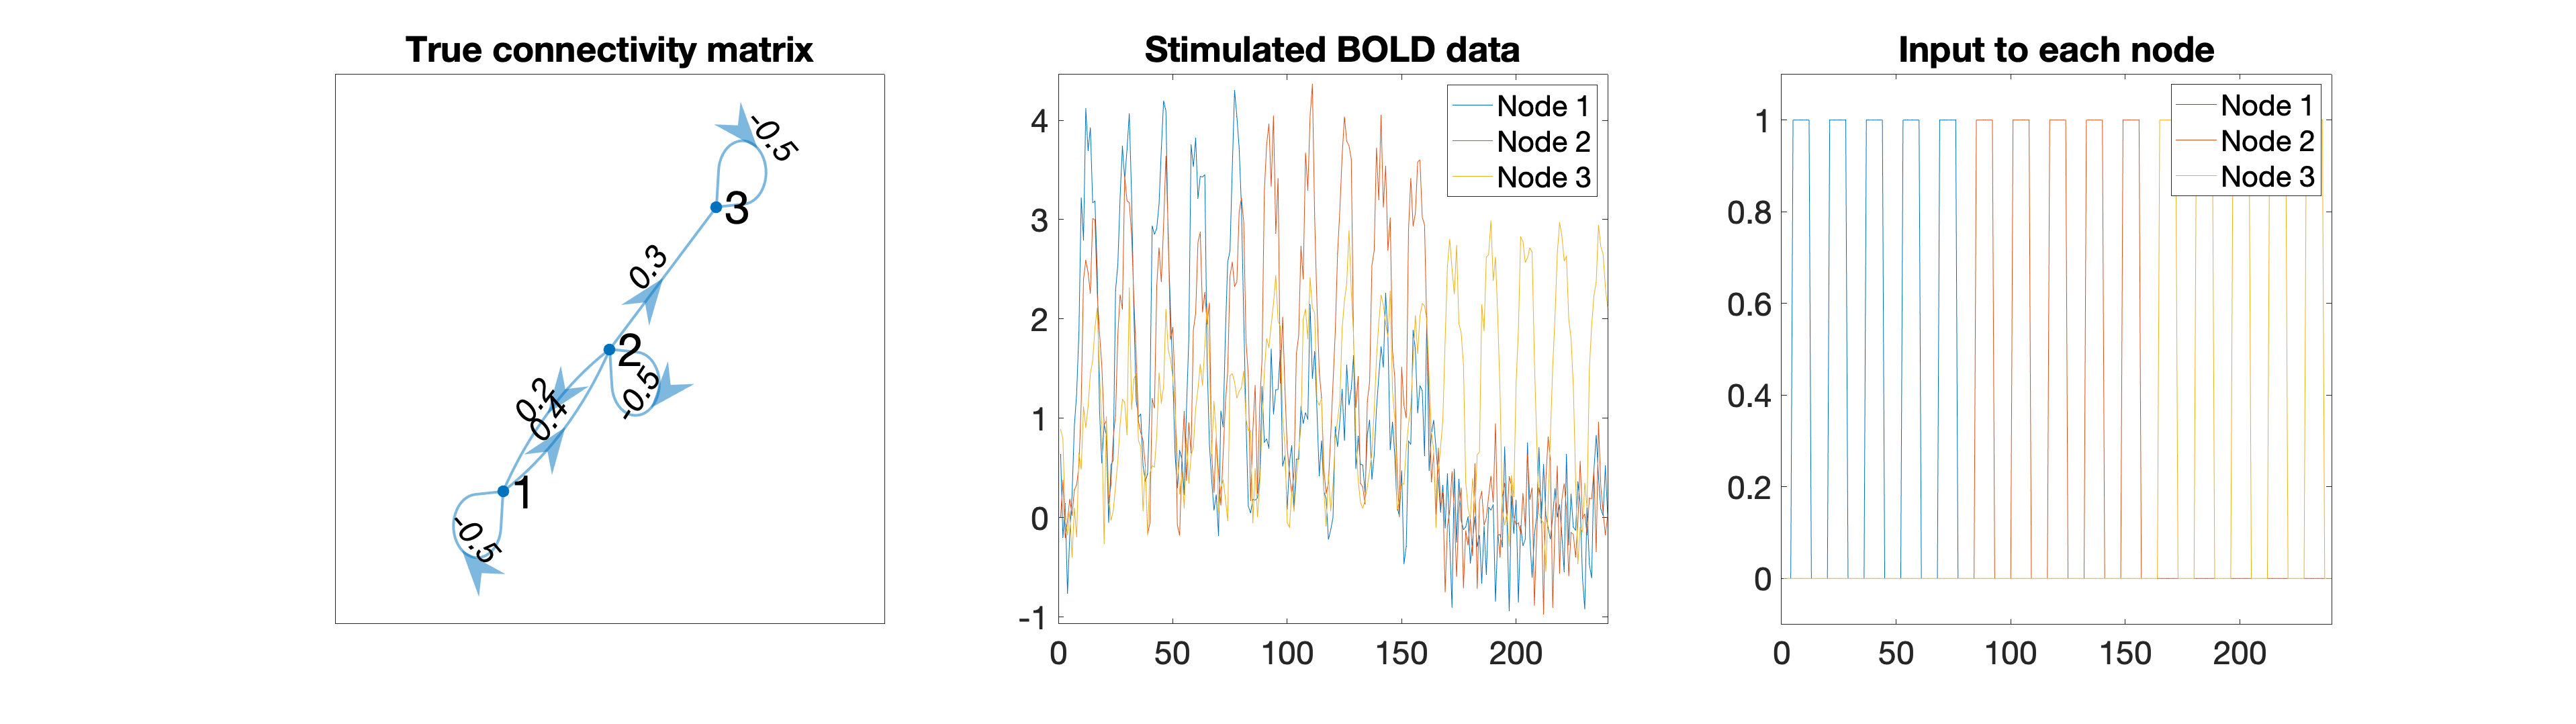

plot_sim_data(DCM_all{1})

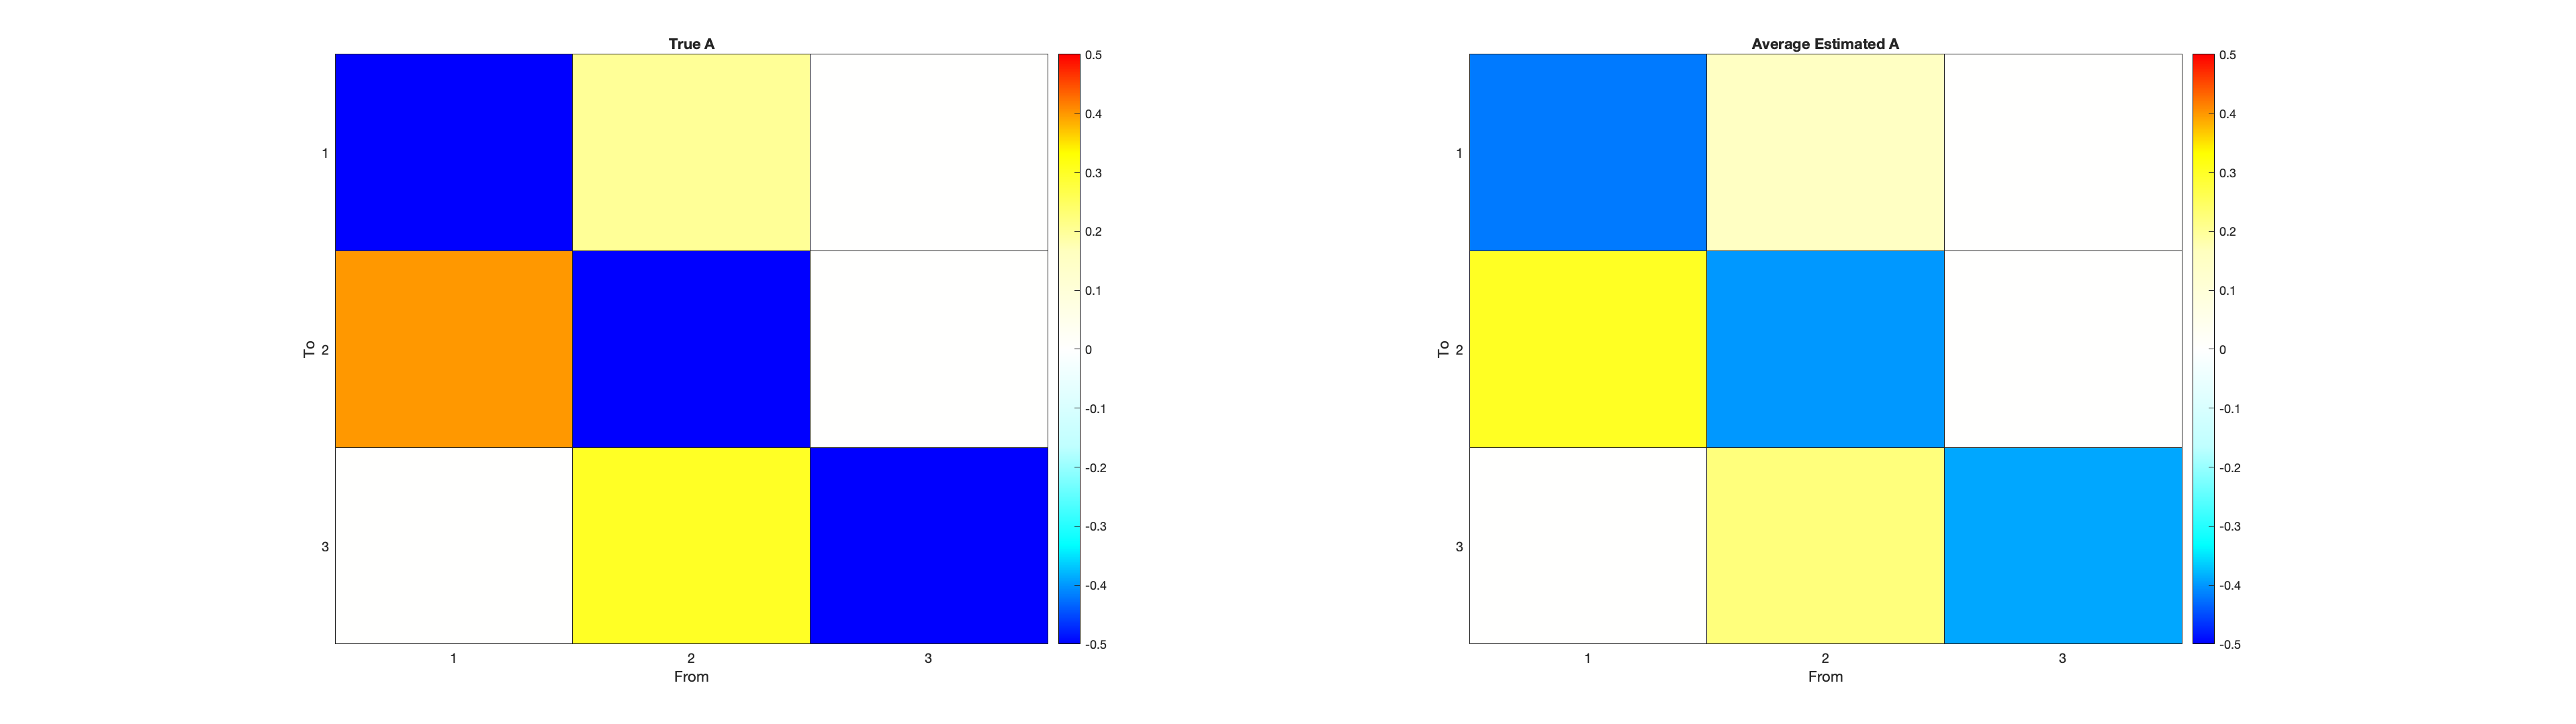

plot_true_est_connectivity(DCM_all{1}, output_all, 1)

## Interim conclusion

Looks like sparse rDCM might be working better if the input is not on all the nodes.

This is in line with the one empirical test for sparse rDCM with task data in Frässle et al. (2020) where they use a motor task that purportedly mainly stimulated the motor cortex nodes and consisted of frequent hand squeezes in each block.

Seems like sparse rDCM is sensitive to task structure and works better the more information you give it about how to prune (e.g. with anatomical connectivity matrices).

## Doubling the network size

stim_options = get_default_stim_options("task");

stim_options.Tp.A = [0 .2  0  0 .5  0;
                    .4  0  0  0  0  0;
                     0 .3  0  0  0  0;
                     0  0 .5  0  0 .4;
                     0  0  0  0  0 .3;
                     0  0  0  0 .2  0];
stim_options.n = size(stim_options.Tp.A, 1);
stim_options.a = ones(stim_options.n);

Specify task timing and stim nodes

on_len = 16;
off_len = 8;
num_blocks = 16;
stim_options.T = num_blocks * (on_len + 2*off_len);
tasktiming = repmat([zeros(1, off_len), ones(1, on_len), zeros(1, off_len)], 1, num_blocks);
stim_options.u_dt = stim_options.TR/16;
tasktiming = interp1(1:stim_options.T, tasktiming, 1:stim_options.u_dt:stim_options.T, "linear");
tasktiming = double(logical(tasktiming));

stim_options.stim_node = [2, 6];
stim_options.Tp.C = zeros(stim_options.n,length(stim_options.stim_node));
for i=1:length(stim_options.stim_node)
    stim_options.Tp.C(stim_options.stim_node(i),i) = 1;
end
stim_options.c = stim_options.Tp.C;

stim_options.u = zeros(length(tasktiming), length(stim_options.stim_node));
for i=1:length(stim_options.stim_node)
    stim_options.u(:, i) = tasktiming;
end

%Stimulate the hub in each community at different blocks (4 blocks at a time)
node_stim_dur = 4*(on_len + 2*off_len)/stim_options.u_dt;

for i=1:4
    if mod(i, 2) == 0
        stim_options.u((i-1)*node_stim_dur+1:node_stim_dur*i, 1) = 0; 
    else
        stim_options.u((i-1)*node_stim_dur+1:node_stim_dur*i, 2) = 0; 
    end
end

Run multiple simulations

num_subj = 20;
DCM_all  = cell(num_subj, 1);
options_all  = cell(num_subj, 1);
output_all  = cell(num_subj, 1);

for i=1:num_subj
    [DCM_all{i}, options_all{i}] = make_task_fmri(stim_options);
    [output_all{i}, options_all{i}] = tapas_rdcm_estimate(DCM_all{i}, 's', options_all{i}, 2);
end 


Regression dynamic causal modeling (rDCM) 

Run model inversion
Processing p0: 19/19
Finalize results

Regression dynamic causal modeling (rDCM) 

Run model inversion
Processing p0: 19/19
Finalize results

Regression dynamic causal modeling (rDCM) 

Run model inversion
Processing p0: 19/19
Finalize results

Regression dynamic causal modeling (rDCM) 

Run model inversion
Processing p0: 19/19
Finalize results

Regression dynamic causal modeling (rDCM) 

Plot true connectivity and input activity

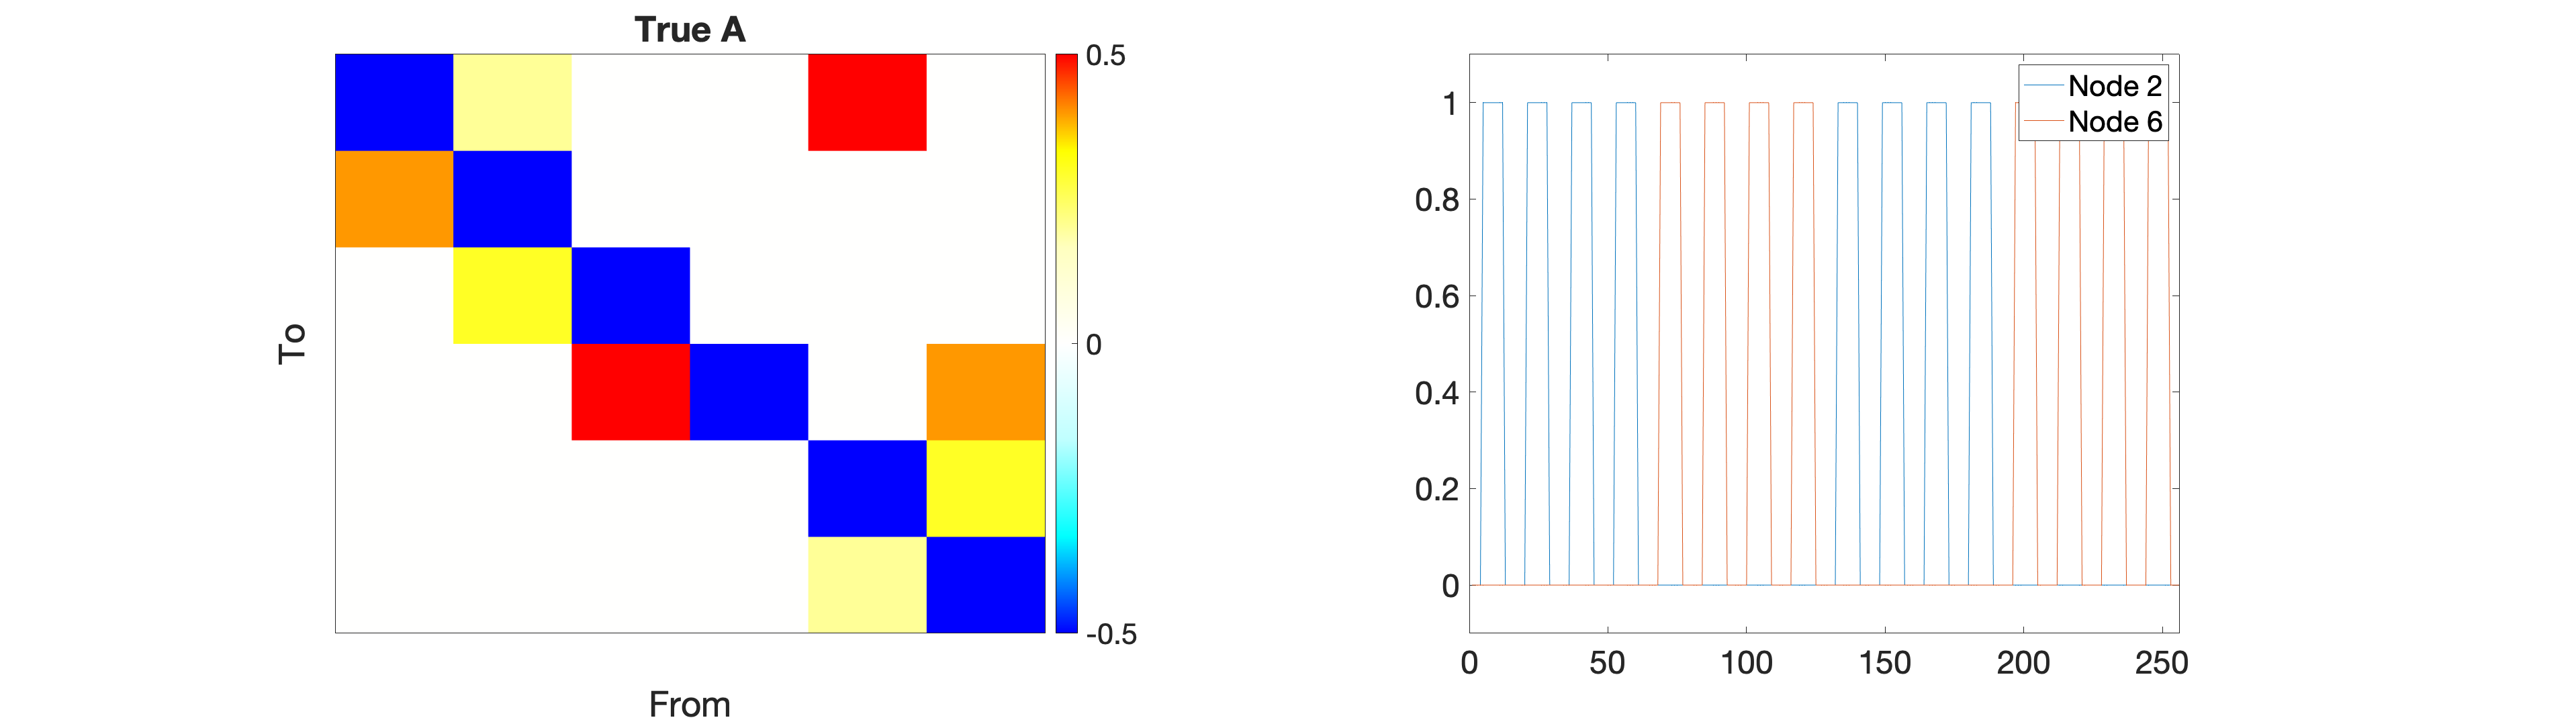

subplot(1, 2, 1)
plot_connectivity(DCM_all{1}.Tp.A);
subplot(1, 2, 2)
r_dt = DCM_all{1}.Y.dt/DCM_all{1}.U.dt;
plot(DCM_all{1}.U.u(1:r_dt:end,:));
axis([0 size(DCM_all{1}.Y.y,1) min(min(DCM_all{1}.U.u))-0.1 max(max(DCM_all{1}.U.u))+0.1])
legend("Node 2", "Node 6")
ax = gca;
ax.FontSize = 24;
set(gcf,'position',[0,0,400,250]);
set(gcf,'Units','normalized','Position',[0 0 1 .5]);

Plot sample timeseries for both communities

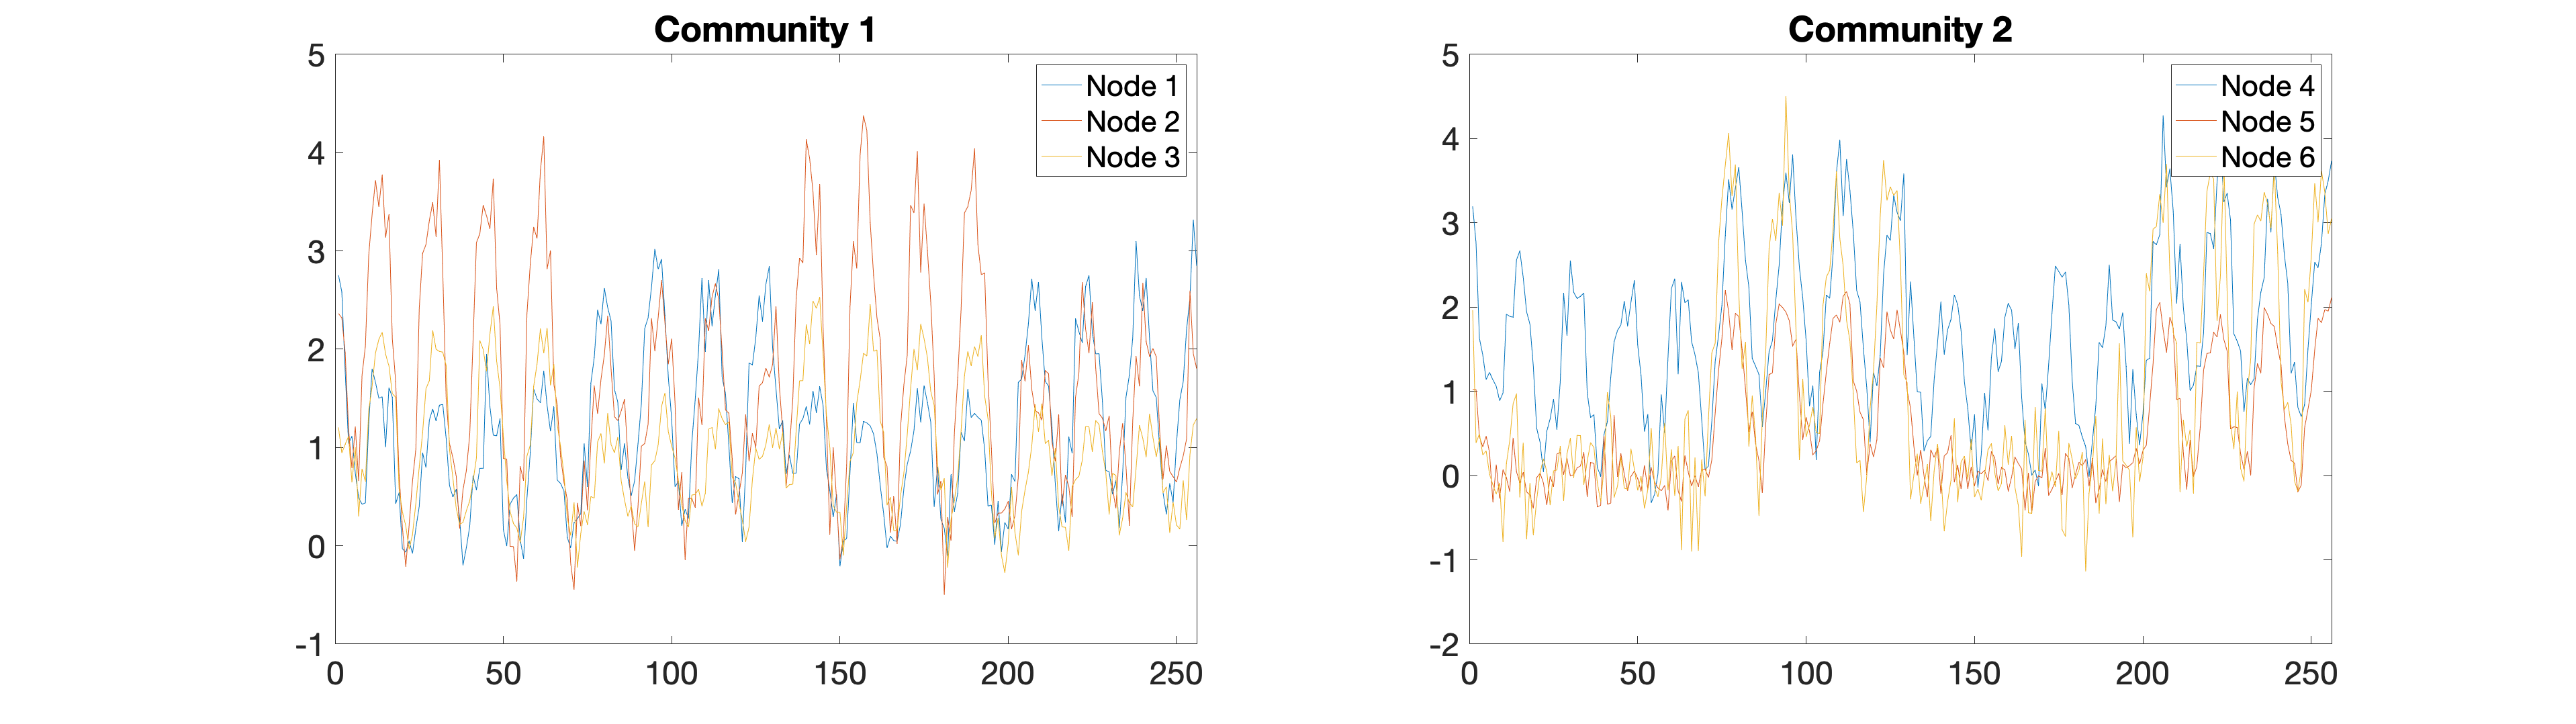

clf

subplot(1, 2, 1)
plot(DCM_all{1}.Y.y(:, 1:3))
legend("Node 1", "Node 2", "Node 3")
xlim([0 size(DCM_all{1}.Y.y, 1)])
title("Community 1")
ax = gca;
ax.FontSize = 24;

subplot(1, 2, 2)
plot(DCM_all{1}.Y.y(:, 4:6))
legend("Node 4", "Node 5", "Node 6")
xlim([0 size(DCM_all{1}.Y.y, 1)])
title("Community 2")
ax = gca;
ax.FontSize = 24;

Plot inversion results

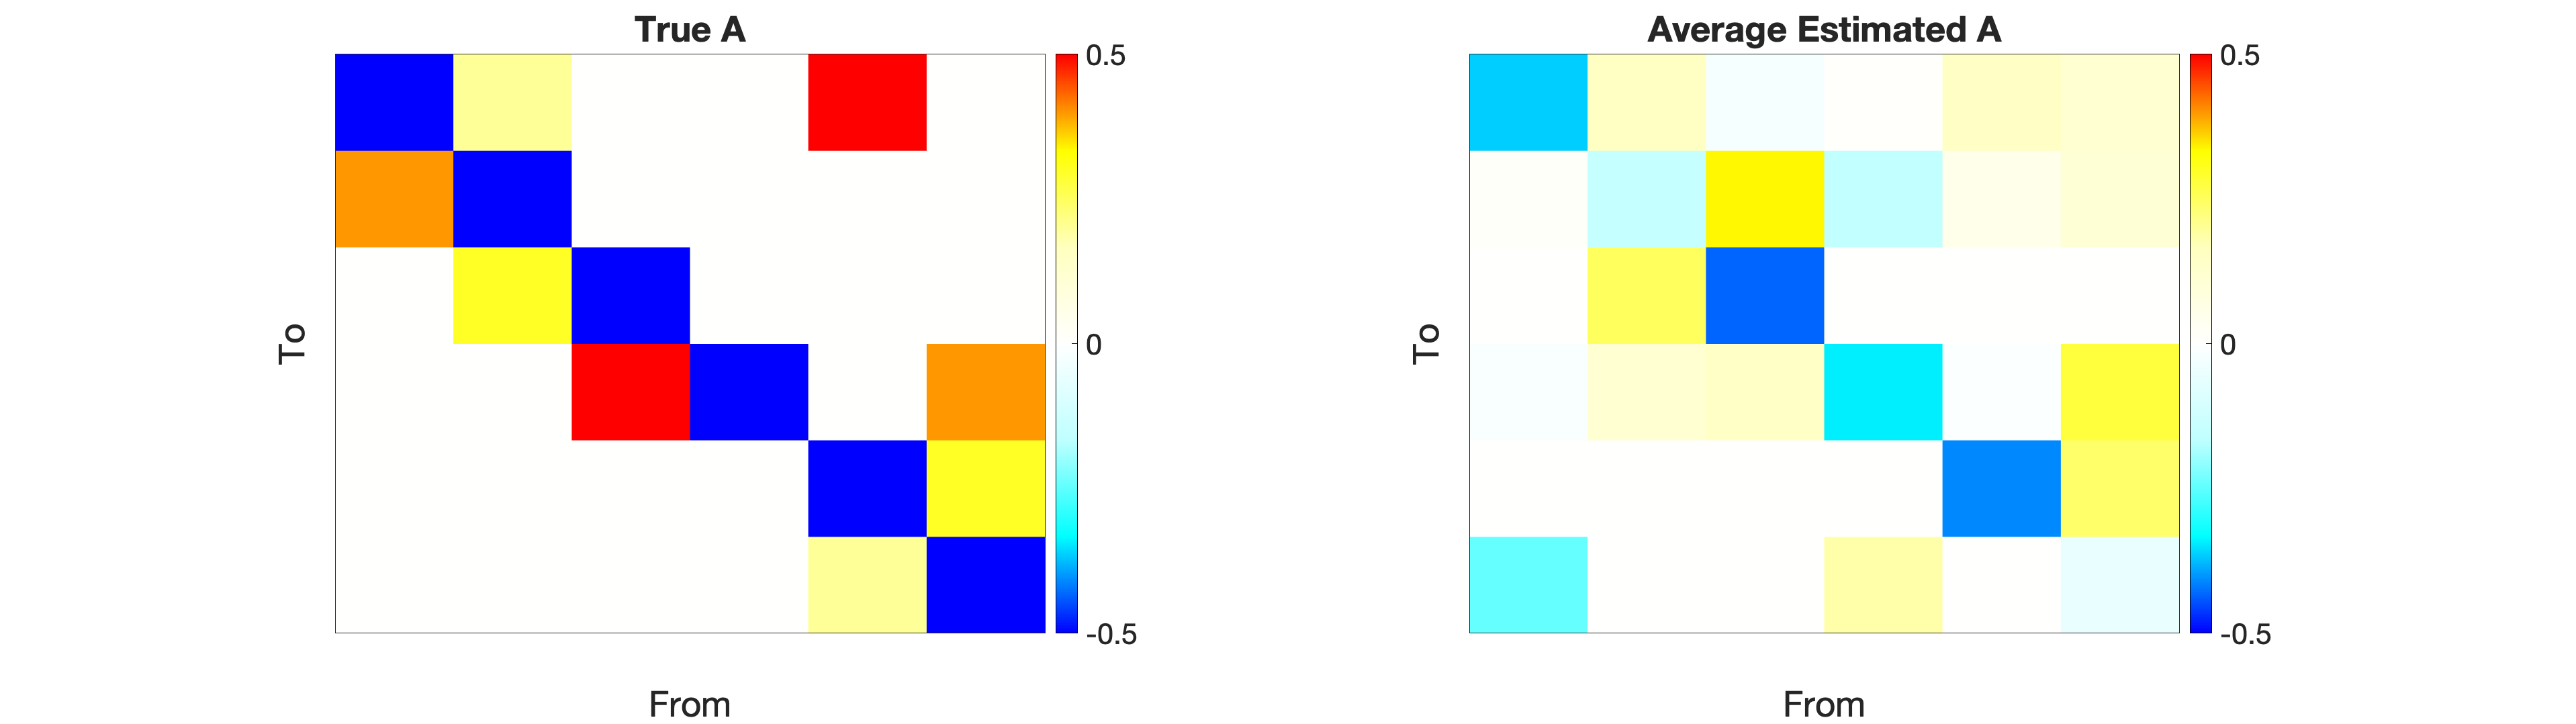

plot_true_est_connectivity(DCM_all{1}, output_all, 1)

Specify task that activates each node at a time.

on_len = 16;
off_len = 8;
num_blocks = 18;
stim_options.T = num_blocks * (on_len + 2*off_len);
tasktiming = repmat([zeros(1, off_len), ones(1, on_len), zeros(1, off_len)], 1, num_blocks);
stim_options.u_dt = stim_options.TR/16;
tasktiming = interp1(1:stim_options.T, tasktiming, 1:stim_options.u_dt:stim_options.T, "linear");
tasktiming = double(logical(tasktiming));

stim_options.stim_node = 1:6;
stim_options.Tp.C = zeros(stim_options.n,length(stim_options.stim_node));
for i=1:length(stim_options.stim_node)
    stim_options.Tp.C(stim_options.stim_node(i),i) = 1;
end
stim_options.c = stim_options.Tp.C;

stim_options.u = zeros(length(tasktiming), length(stim_options.stim_node));
for i=1:length(stim_options.stim_node)
    stim_options.u(:, i) = tasktiming;
end

%Stimulate the hub in each community at different blocks (4 blocks at a time)
node_stim_dur = 3*(on_len + 2*off_len)/stim_options.u_dt;

for i=1:stim_options.n
    cur_nodes = stim_options.stim_node(stim_options.stim_node~=i);
    stim_options.u((i-1)*node_stim_dur+1:node_stim_dur*i, cur_nodes) = 0; 
end

Simulate 20 subjects and invert the model

num_subj = 20;
DCM_all  = cell(num_subj, 1);
options_all  = cell(num_subj, 1);
output_all  = cell(num_subj, 1);

for i=1:num_subj
    [DCM_all{i}, options_all{i}] = make_task_fmri(stim_options);
    [output_all{i}, options_all{i}] = tapas_rdcm_estimate(DCM_all{i}, 's', options_all{i}, 2);
end 


Regression dynamic causal modeling (rDCM) 

Run model inversion
Processing p0: 19/19
Finalize results

Regression dynamic causal modeling (rDCM) 

Run model inversion
Processing p0: 19/19
Finalize results

Regression dynamic causal modeling (rDCM) 

Run model inversion
Processing p0: 19/19
Finalize results

Regression dynamic causal modeling (rDCM) 

Run model inversion
Processing p0: 19/19
Finalize results

Regression dynamic causal modeling (rDCM) 

Plot true connectivity and task 

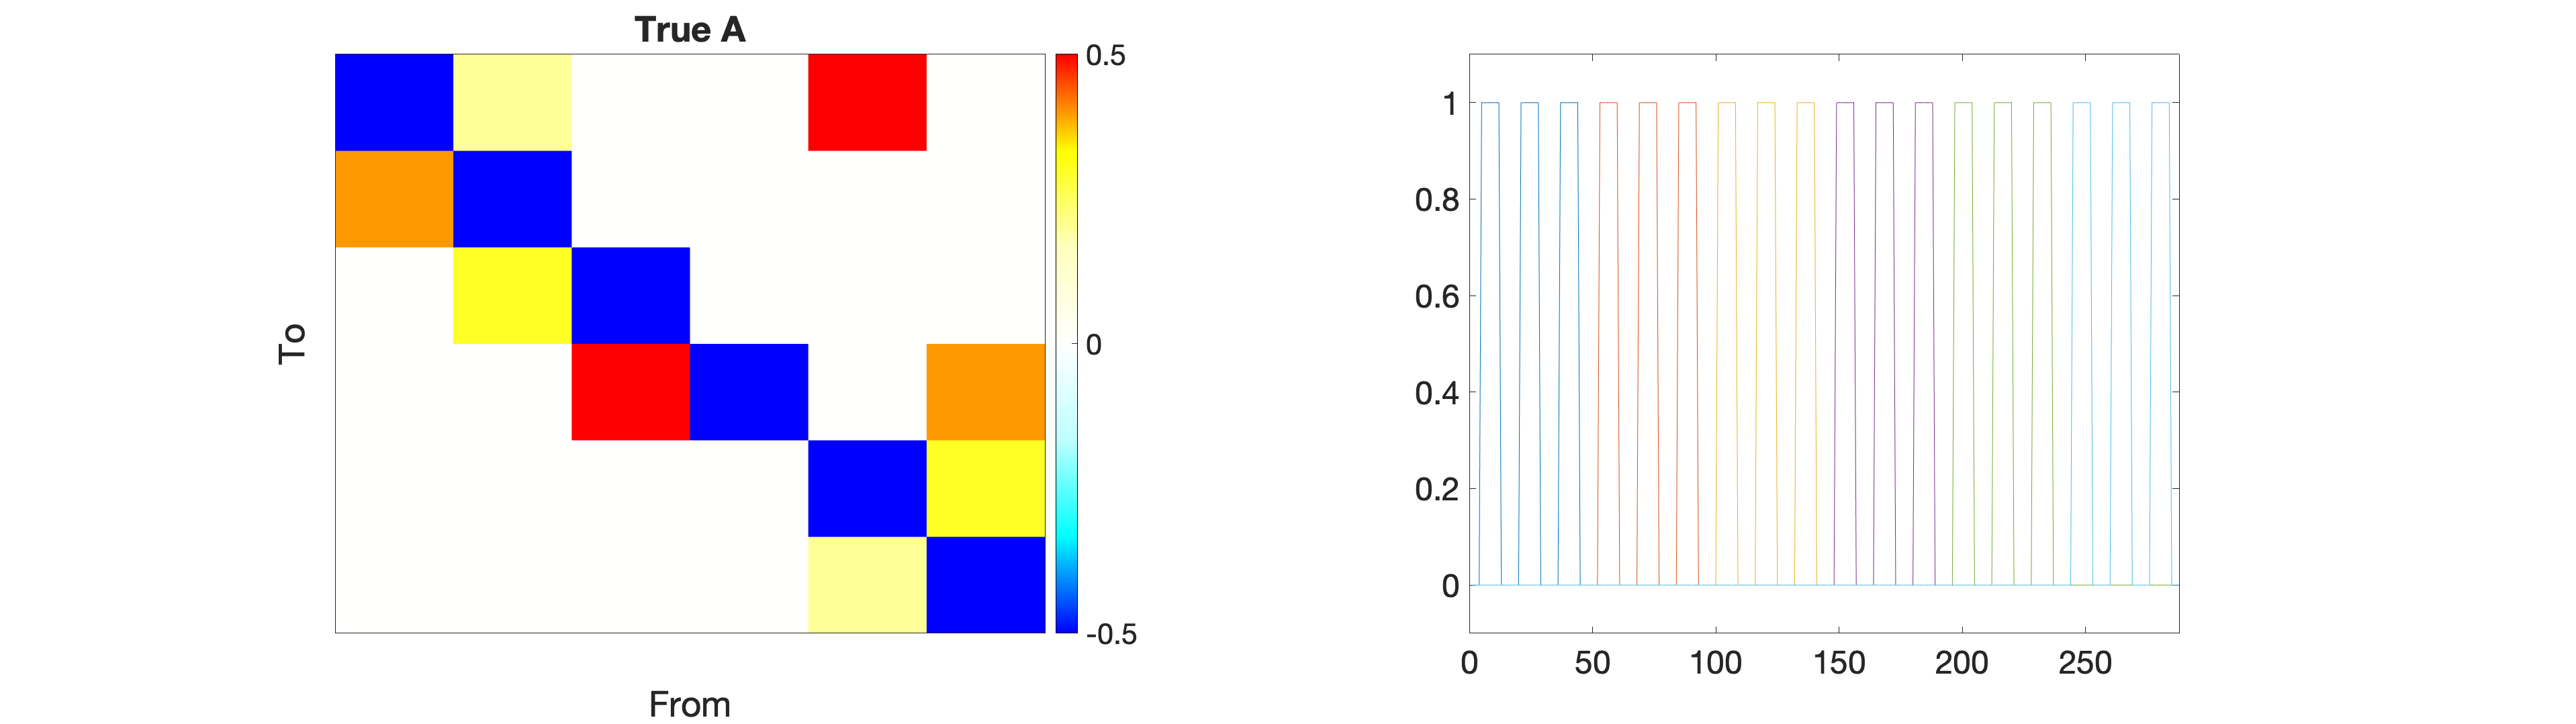

subplot(1, 2, 1)
plot_connectivity(DCM_all{1}.Tp.A);

subplot(1, 2, 2)
r_dt = DCM_all{1}.Y.dt/DCM_all{1}.U.dt;
plot(DCM_all{1}.U.u(1:r_dt:end,:));
axis([0 size(DCM_all{1}.Y.y,1) min(min(DCM_all{1}.U.u))-0.1 max(max(DCM_all{1}.U.u))+0.1])
ax = gca;
ax.FontSize = 24;
set(gcf,'position',[0,0,400,250]);
set(gcf,'Units','normalized','Position',[0 0 1 .5]);

Plot example timeseries

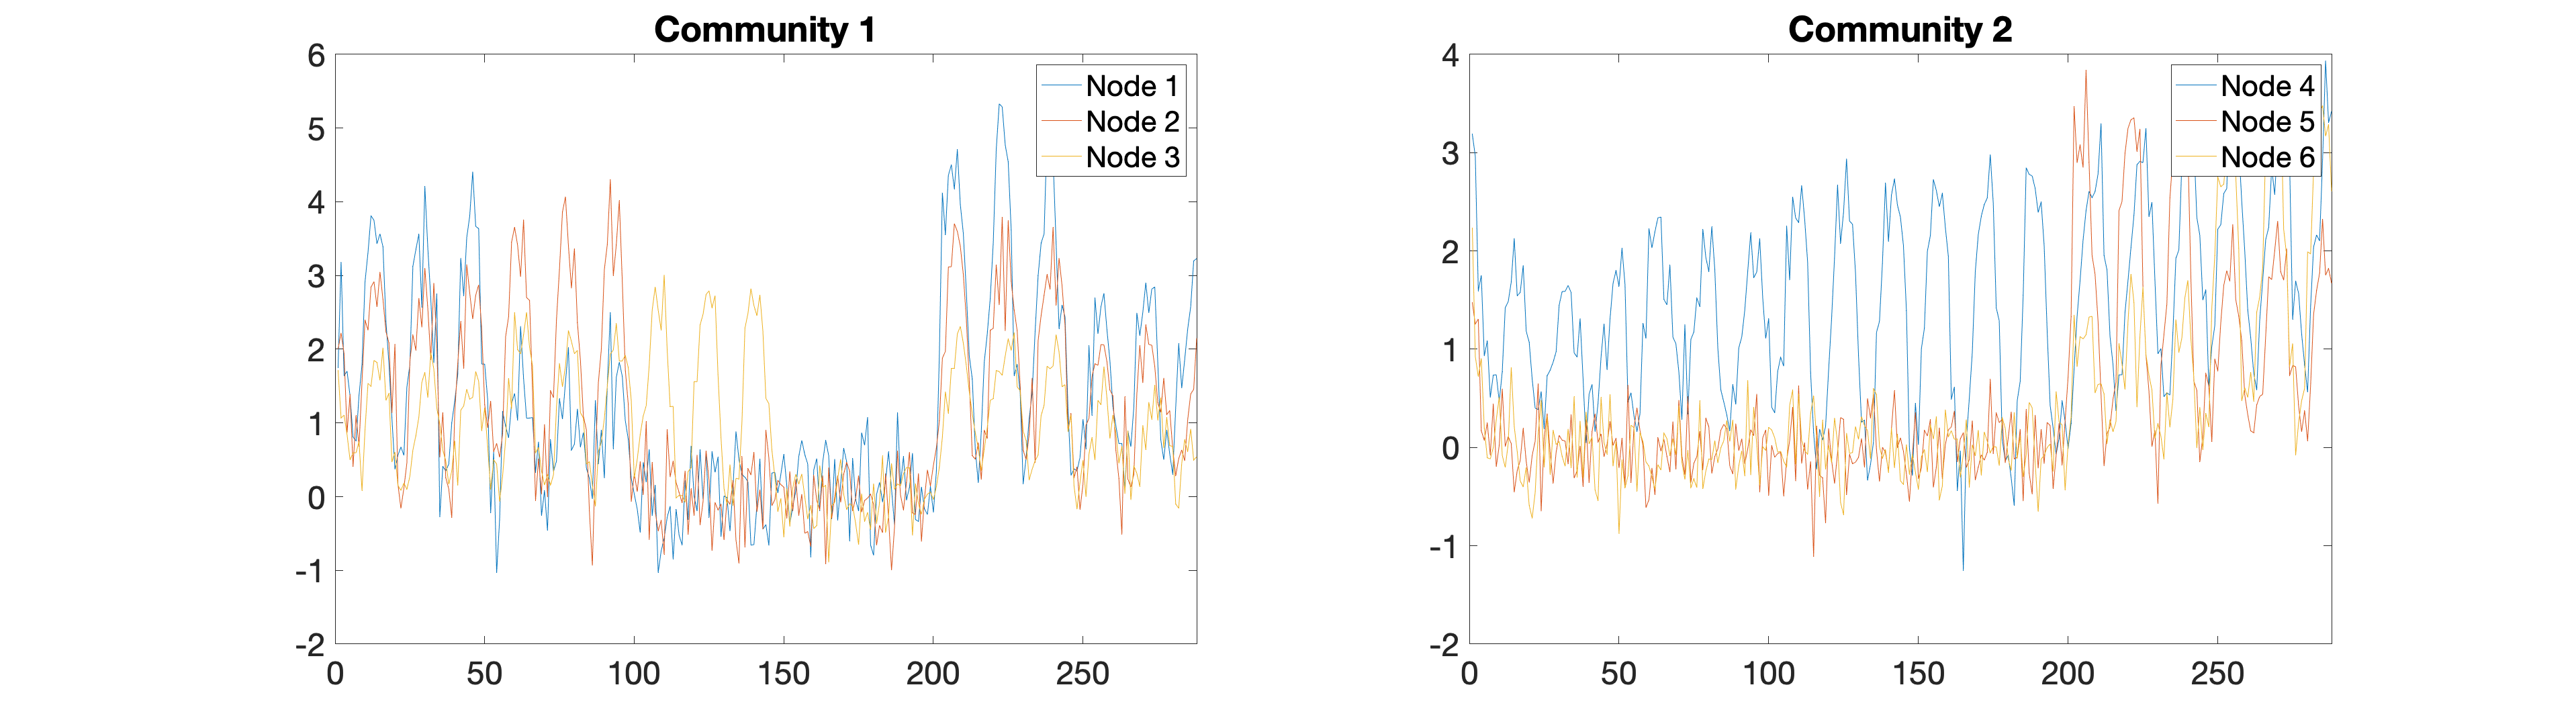

clf

subplot(1, 2, 1)
plot(DCM_all{1}.Y.y(:, 1:3))
legend("Node 1", "Node 2", "Node 3")
xlim([0 size(DCM_all{1}.Y.y, 1)])
title("Community 1")
ax = gca;
ax.FontSize = 24;

subplot(1, 2, 2)
plot(DCM_all{1}.Y.y(:, 4:6))
legend("Node 4", "Node 5", "Node 6")
xlim([0 size(DCM_all{1}.Y.y, 1)])
title("Community 2")
ax = gca;
ax.FontSize = 24;

Plot inversion results

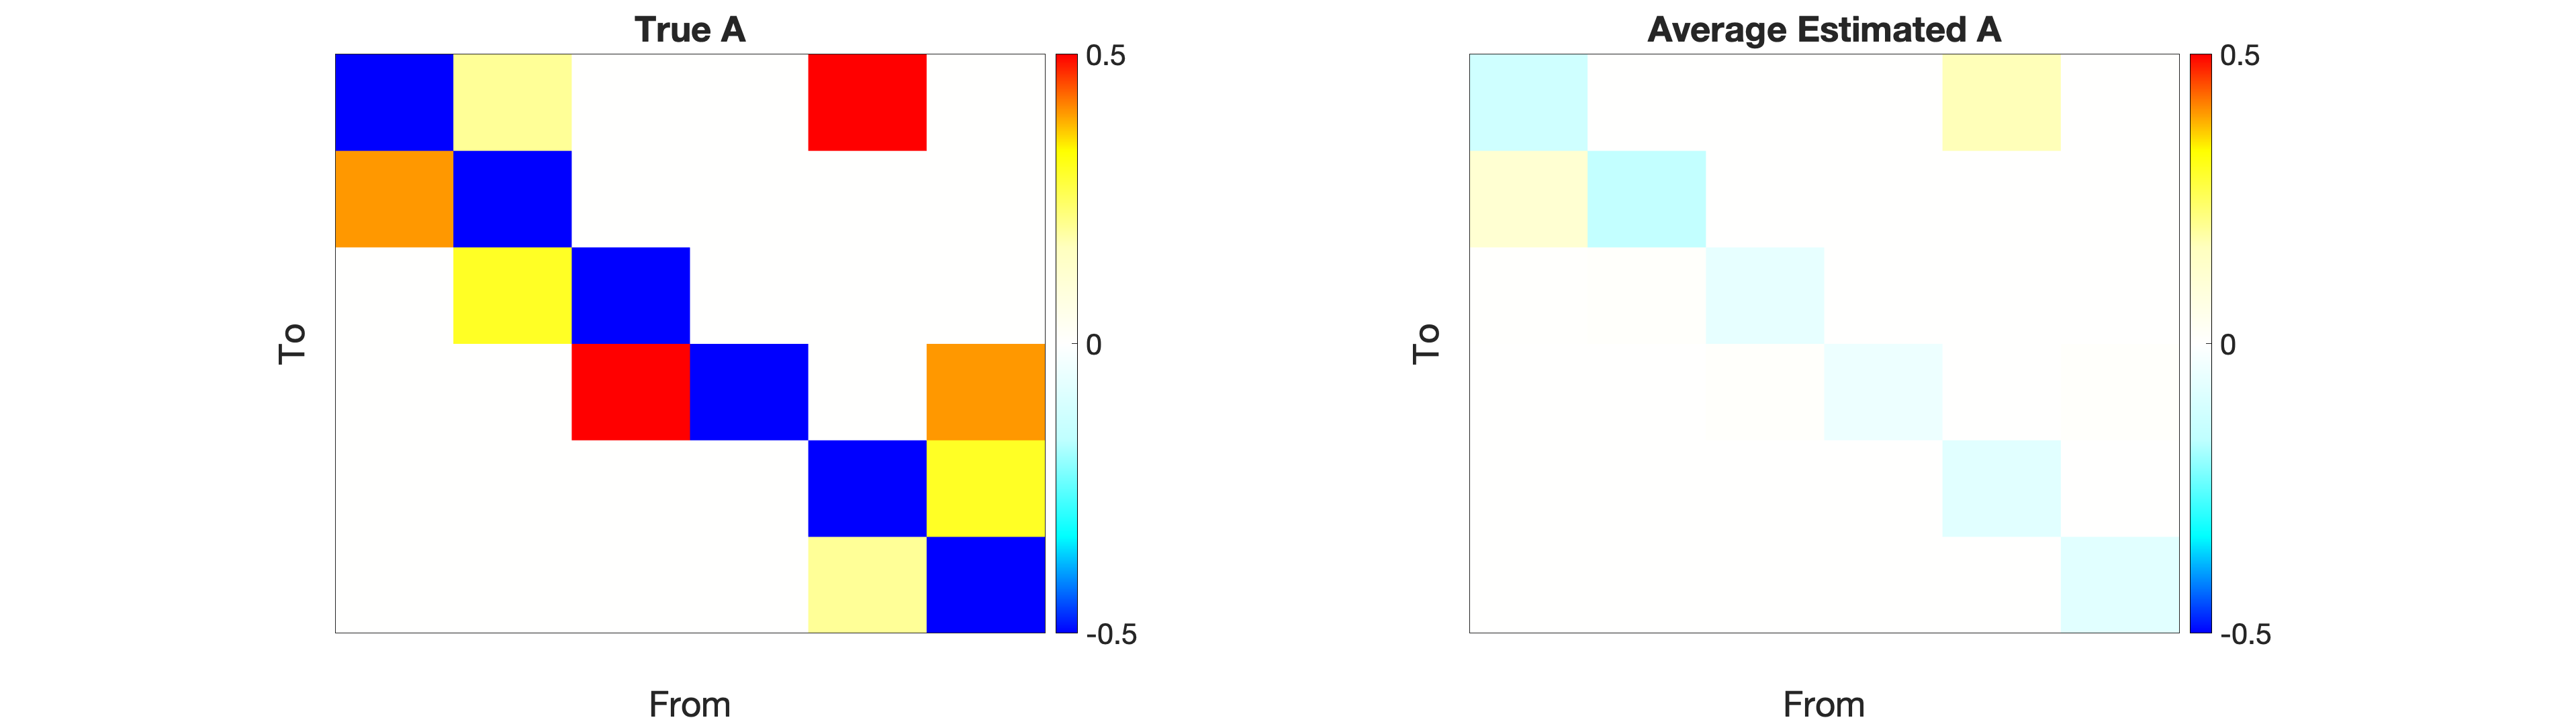

plot_true_est_connectivity(DCM_all{1}, output_all, 1)